# Lab 4

## Kurt Delegard

## PHYS 434 AB

#### Time spent drafting: 13 hours

clear;
h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:)

ans =    940680016         315          45          10


This dataset, which we have named "mydata", is data from a gamma-ray satellite in low-Earth orbit. This satellite measures the number of particles detected every 100 milliseconds and orbits the Earth approximately once every 90 minutes. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays. The columns of data included in this dataset are: **time** (gps seconds), **solar phase **(degrees), **Earth longitude **(degrees), and **particle counts **(number of particles).

We can explore this data using a variety of plots. First, let us plot the first 7.5 hours of data (corresponding to approximately 5 orbits around Earth) for solar phase and Earth longitude to observe their periodicity:

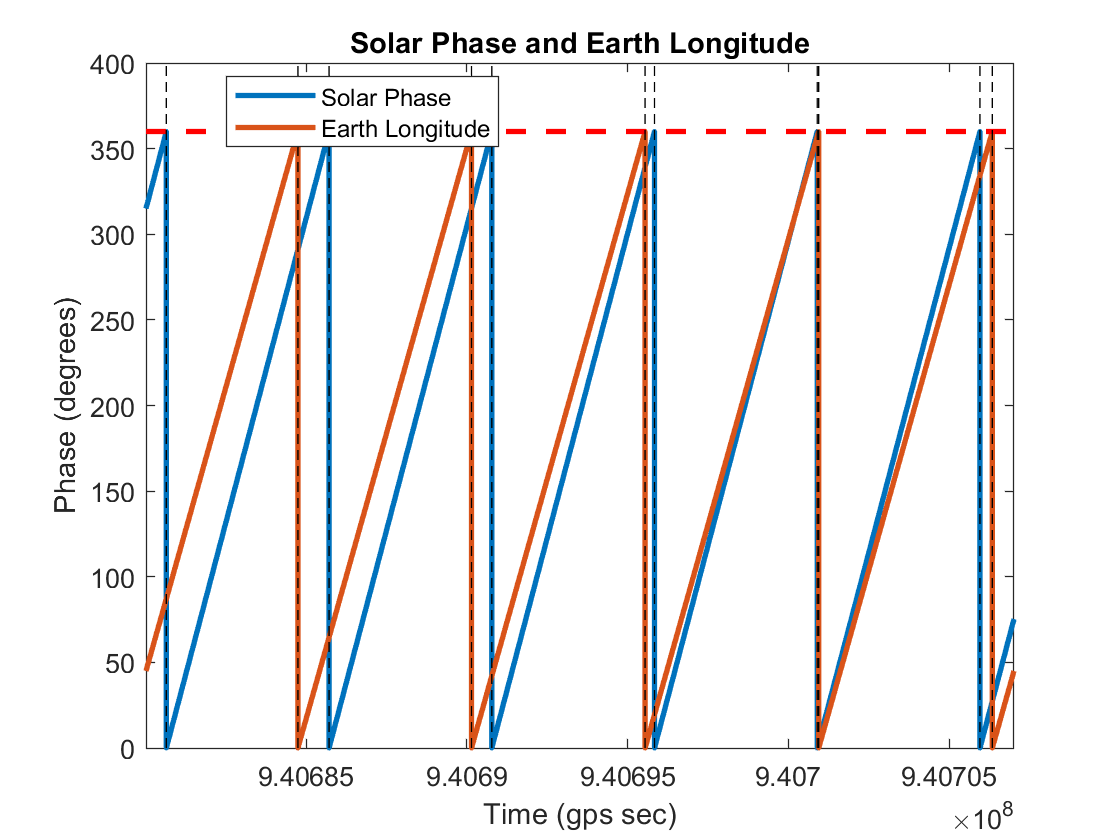

clc;
clf;
times = mydata(:, 1);
solar_phases = mydata(:, 2);
earth_longitude = mydata(:, 3);
particle_counts = mydata(:, 4);

%plot 5 periods
endtime = 5400*50;

plot(times(1:endtime), solar_phases(1:endtime), 'linewidth', 2), hold on;
plot(times(1:endtime), earth_longitude(1:endtime), 'linewidth', 2);
plot([times(1), times(endtime)], [360, 360], 'r--', 'linewidth', 2);
xlim([times(1), times(endtime)]);
ylim([0 400])
title('Solar Phase and Earth Longitude');
xlabel('Time (gps sec)');
ylabel('Phase (degrees)');
legend('Solar Phase', 'Earth Longitude', 'location', 'best');


solar_period_times = times(islocalmin(solar_phases));
for ii = solar_period_times(1:6)
    plot([ii, ii], [0, 500], 'k--', 'HandleVisibility', "off");
end
earth_period_times = times(islocalmin(earth_longitude));
for ii = earth_period_times(1:6)
    plot([ii, ii], [0, 500], 'k--', 'HandleVisibility', "off");
end

Here we can see that the solar phase and Earth longitude are linear and periodic, but with different periods:

%units of minutes
solar_period = mean(solar_period_times(2:2:end) - solar_period_times(1:2:end - 1)) ./ 60

solar_period = 84.3611

%units of minutes
earth_period = mean(earth_period_times(2:2:end) - earth_period_times(1:2:end - 1)) ./ 60

earth_period = 90

The earth period turns out to be exactly 90 minutes, while the solar period varies and has a slightly shorter period.

Next, we can plot the first 7.5 hours of data for particle counts to observe any time-related patterns:

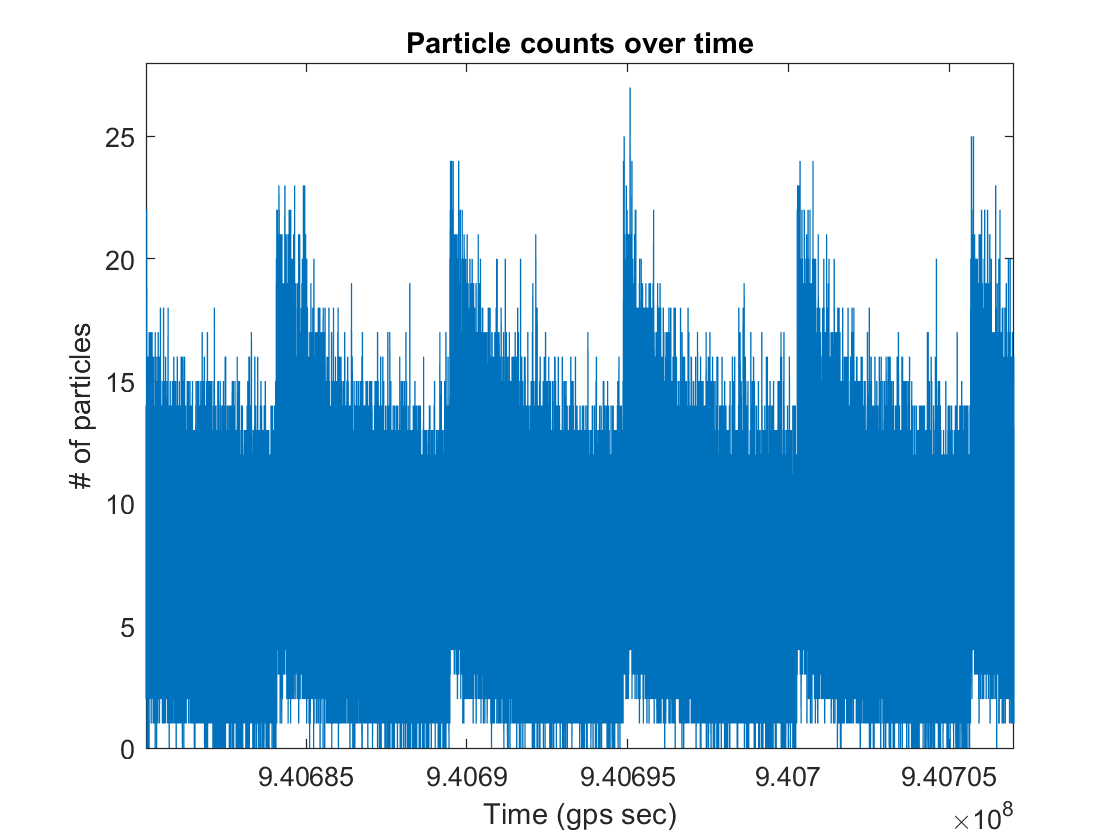

clf;
plot(times(1:endtime), particle_counts(1:endtime));
xlim([times(1), times(endtime)])
ylim([0 28]);
title('Particle counts over time');
xlabel('Time (gps sec)');
ylabel('# of particles')

We can see that there are certain periodic times throughout the data (spikes) where the number of cosmic rays is very high. 

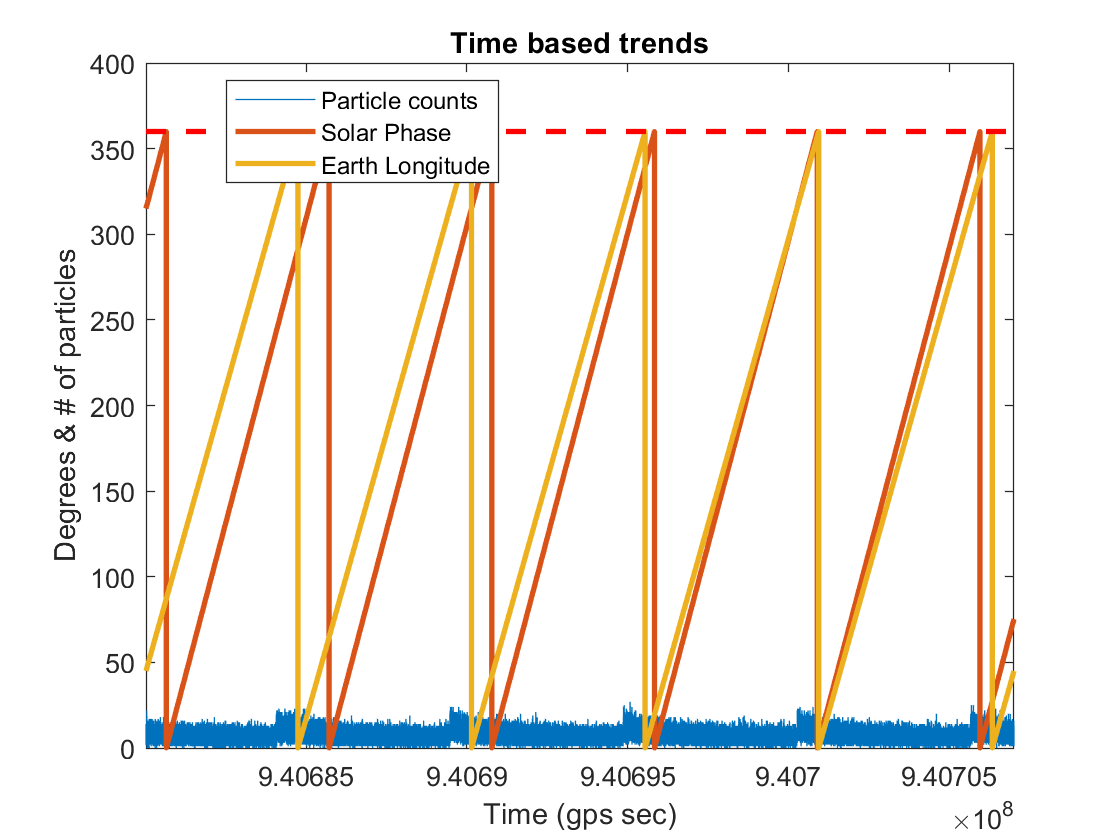

clf;
plot(times(1:endtime), particle_counts(1:endtime)), hold on;
plot(times(1:endtime), solar_phases(1:endtime), 'linewidth', 2);
plot(times(1:endtime), earth_longitude(1:endtime), 'linewidth', 2);
plot([times(1), times(endtime)], [360, 360], 'r--', 'linewidth', 2);
xlim([times(1), times(endtime)]);
title('Time based trends');
xlabel('Time (gps sec)')
ylabel('Degrees & # of particles')
legend('Particle counts','Solar Phase', 'Earth Longitude', 'location', 'best');

We can more accurately find the periods of the three sets of data by analyzing the Fourier transform of the data:

[f, fourier_solar] = fouriern(solar_phases);
[f, fourier_earth] = fouriern(earth_longitude);
[f, fourier_particle] = fouriern(particle_counts);

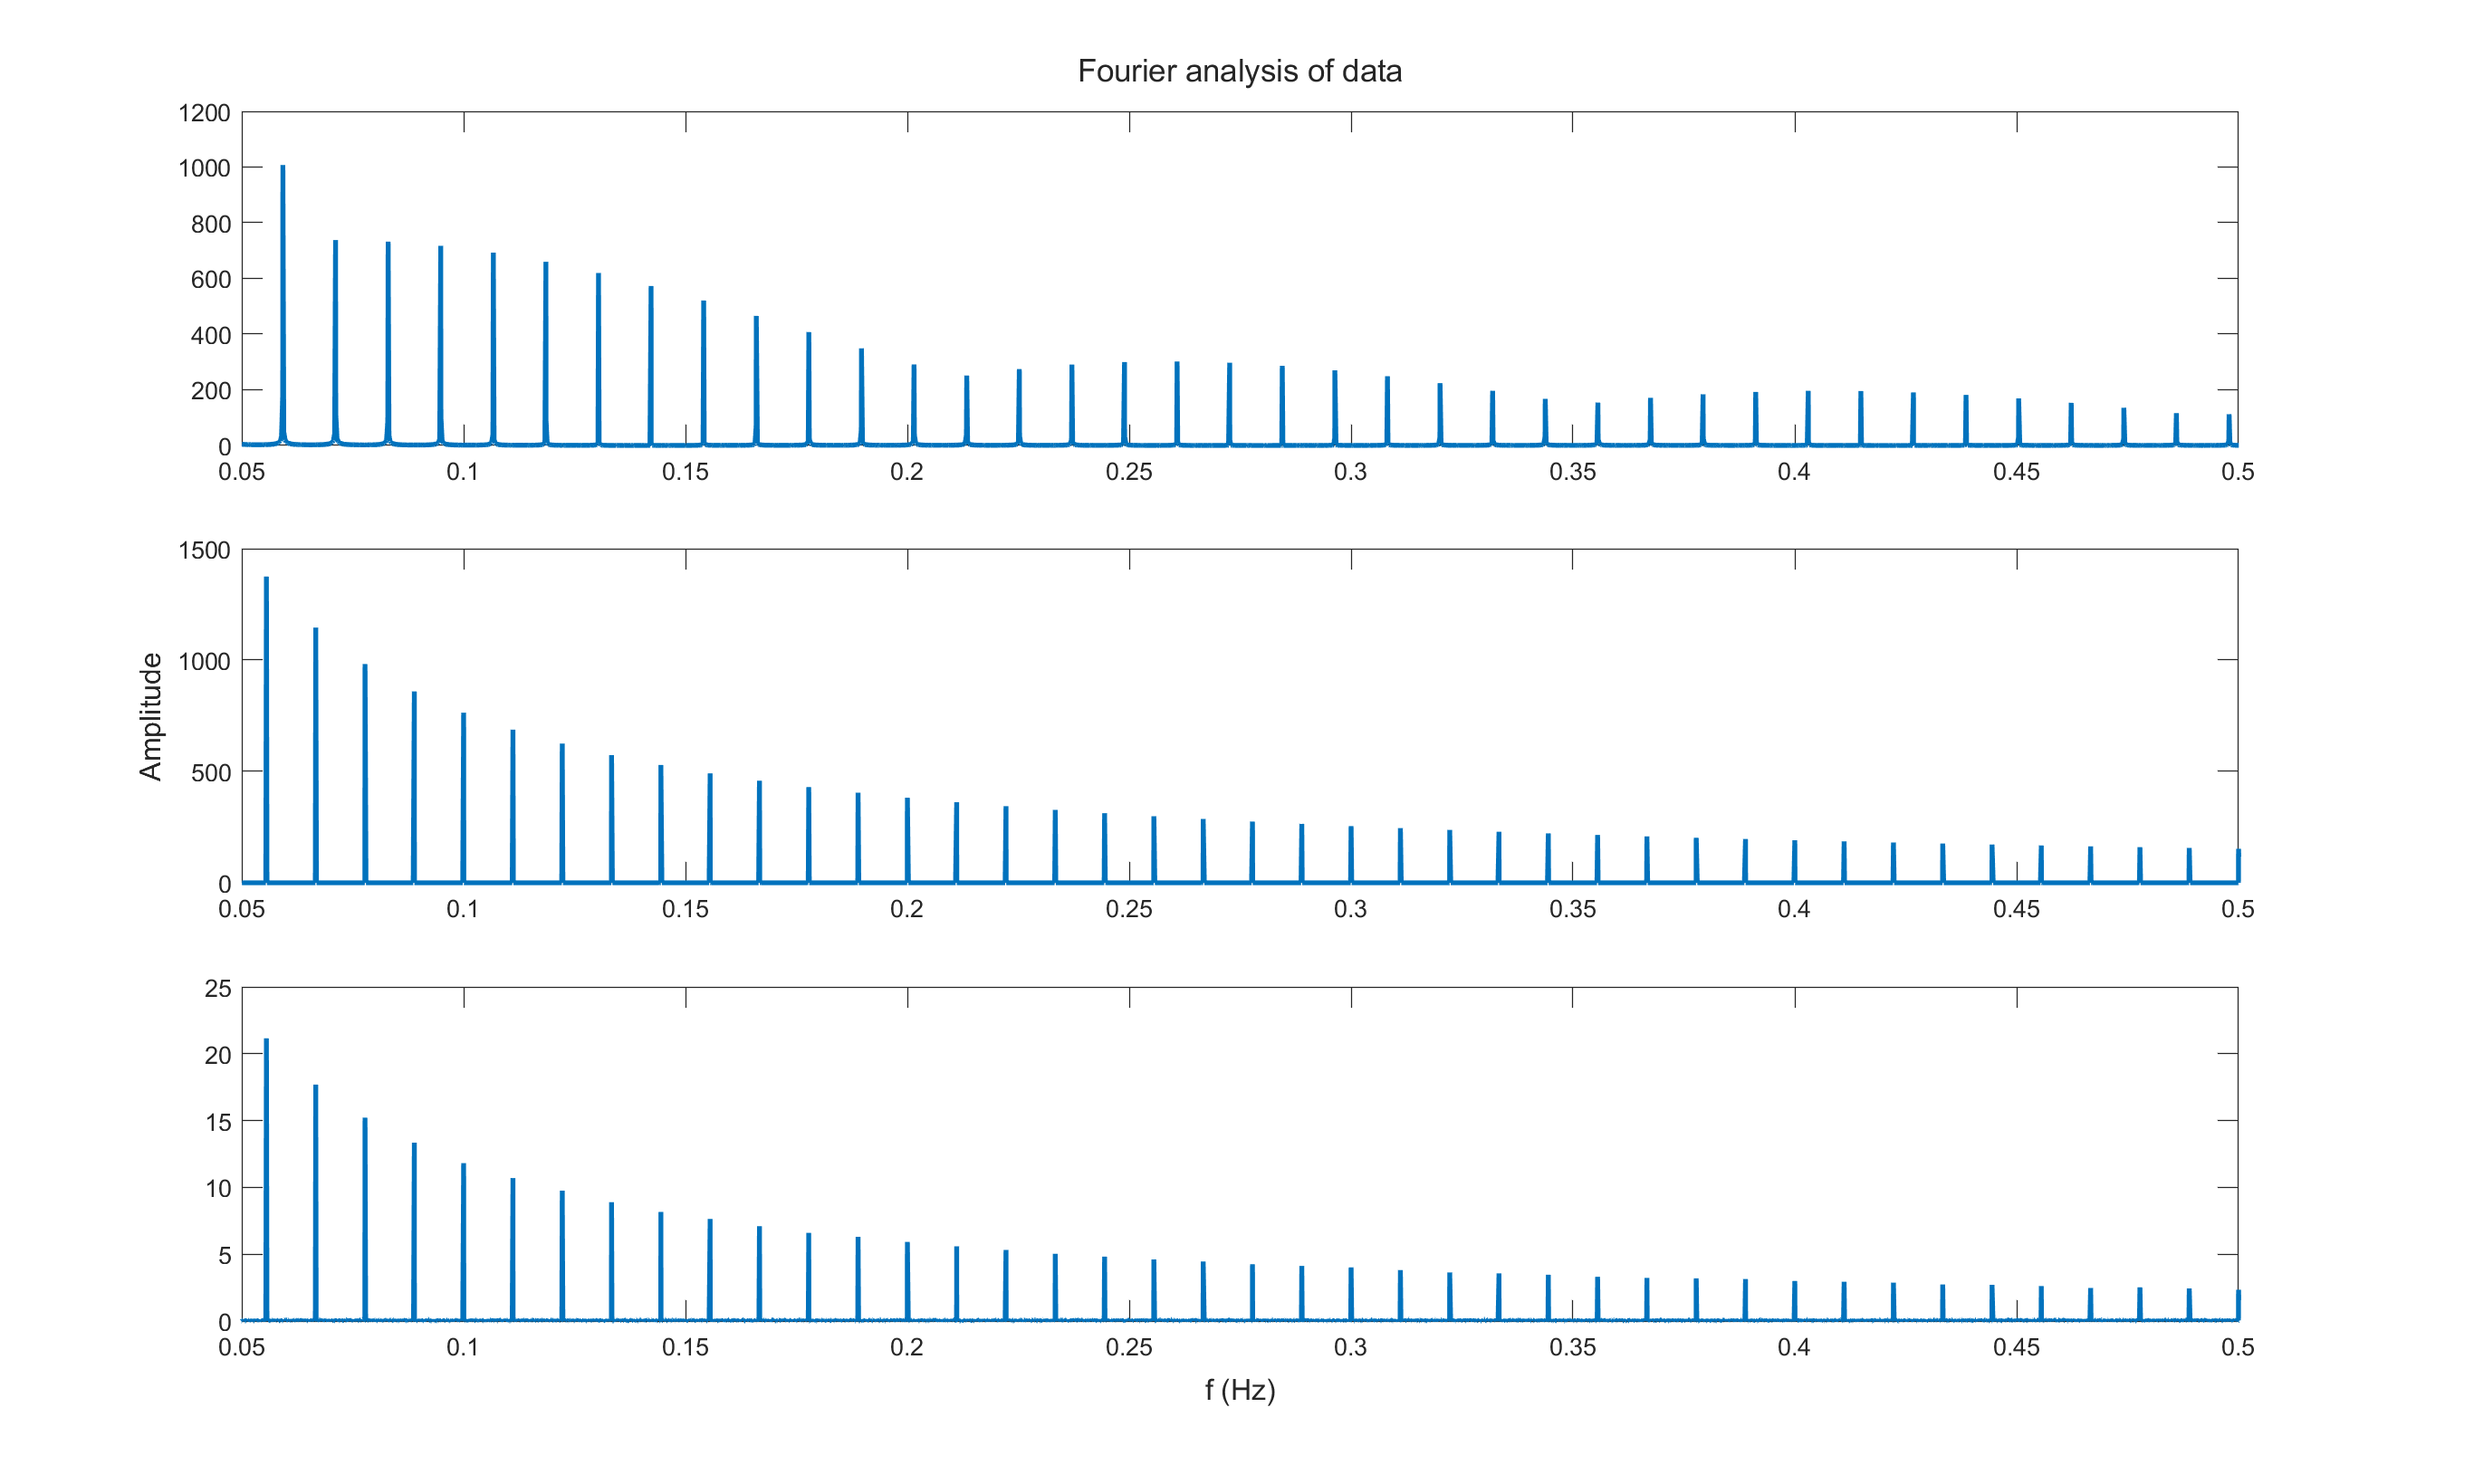

particle_frequencies = f(fourier_particle > 10);
earth_frequencies = f(fourier_earth > 1e3);
solar_frequencies = f(fourier_solar > 1e3);

clf;
t0 = tiledlayout(3, 1);

t1 = nexttile;
title('Solar phase');
plot(f(f > 0.05), fourier_solar((f > 0.05)), 'linewidth', 2), hold on;
xlim([0.05 0.5]);

t2 = nexttile;
title('Earth longitude');
plot(f(f > 0.05), fourier_earth((f > 0.05)), 'linewidth', 2);
xlim([0.05 0.5]);

t3 = nexttile;
title('Particle data');
plot(f(f > 0.05), fourier_particle((f > 0.05)), 'linewidth', 2);
xlim([0.05 0.5]);

title(t0, 'Fourier analysis of data')
xlabel(t0, 'f (Hz)');
ylabel(t0, 'Amplitude');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

solar_period = 1 ./ solar_frequencies(2)

solar_period = 84.3750

earth_period = 1 ./ earth_frequencies(2)

earth_period = 90

particle_period = 1 ./ particle_frequencies(2)

particle_period = 90

We can see that the period of the Earth longitude and the period of the particle count data is the same. Therefore, we can assume that the fluctuations in the particle count data is correlated to the satellite's position in its orbit around the Earth. 

Looking at the distribution of values for the particle data:

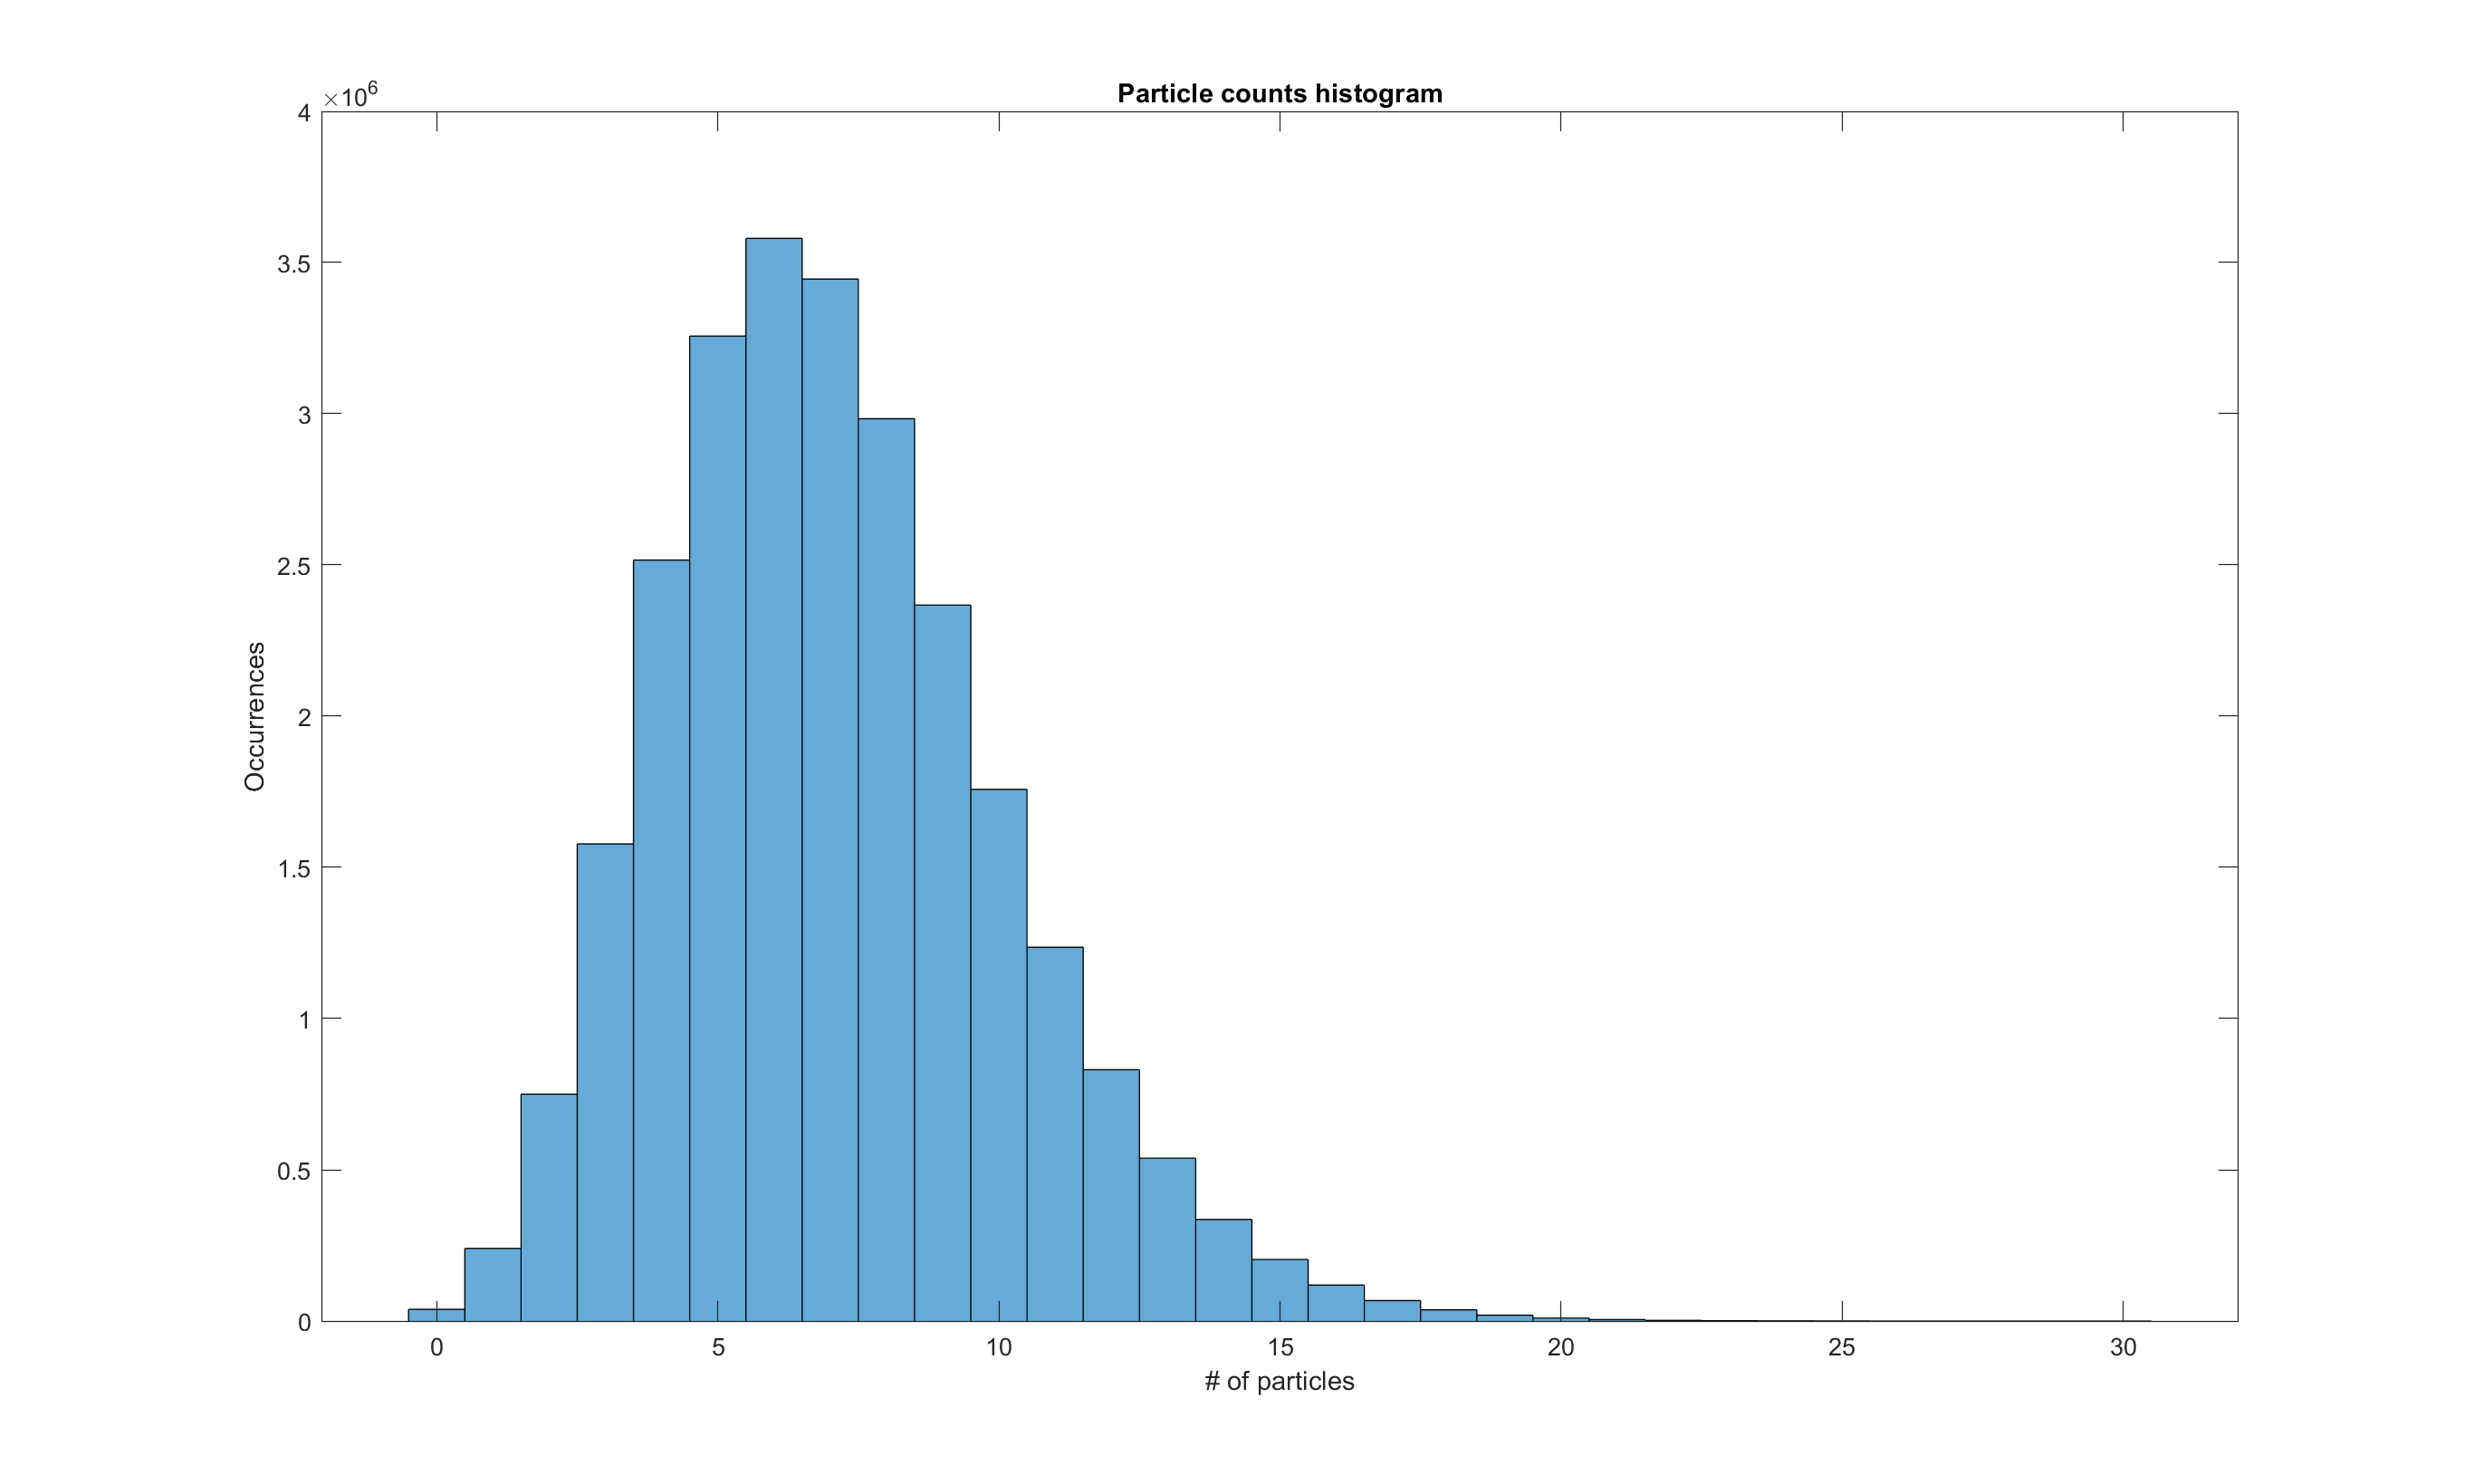

clf;
histogram(particle_counts, 'BinMethod', 'Integers');
title('Particle counts histogram');
xlabel('# of particles');
ylabel('Occurrences');

We expect this distribution to be best approximated by a Poisson distribution, since it is based on the random arrival of cosmic rays within a specific time interval. The data appears to have a mean of approximately 6, so we can see if a Poisson distribution with $\lambda =6$ will accurately model the data:

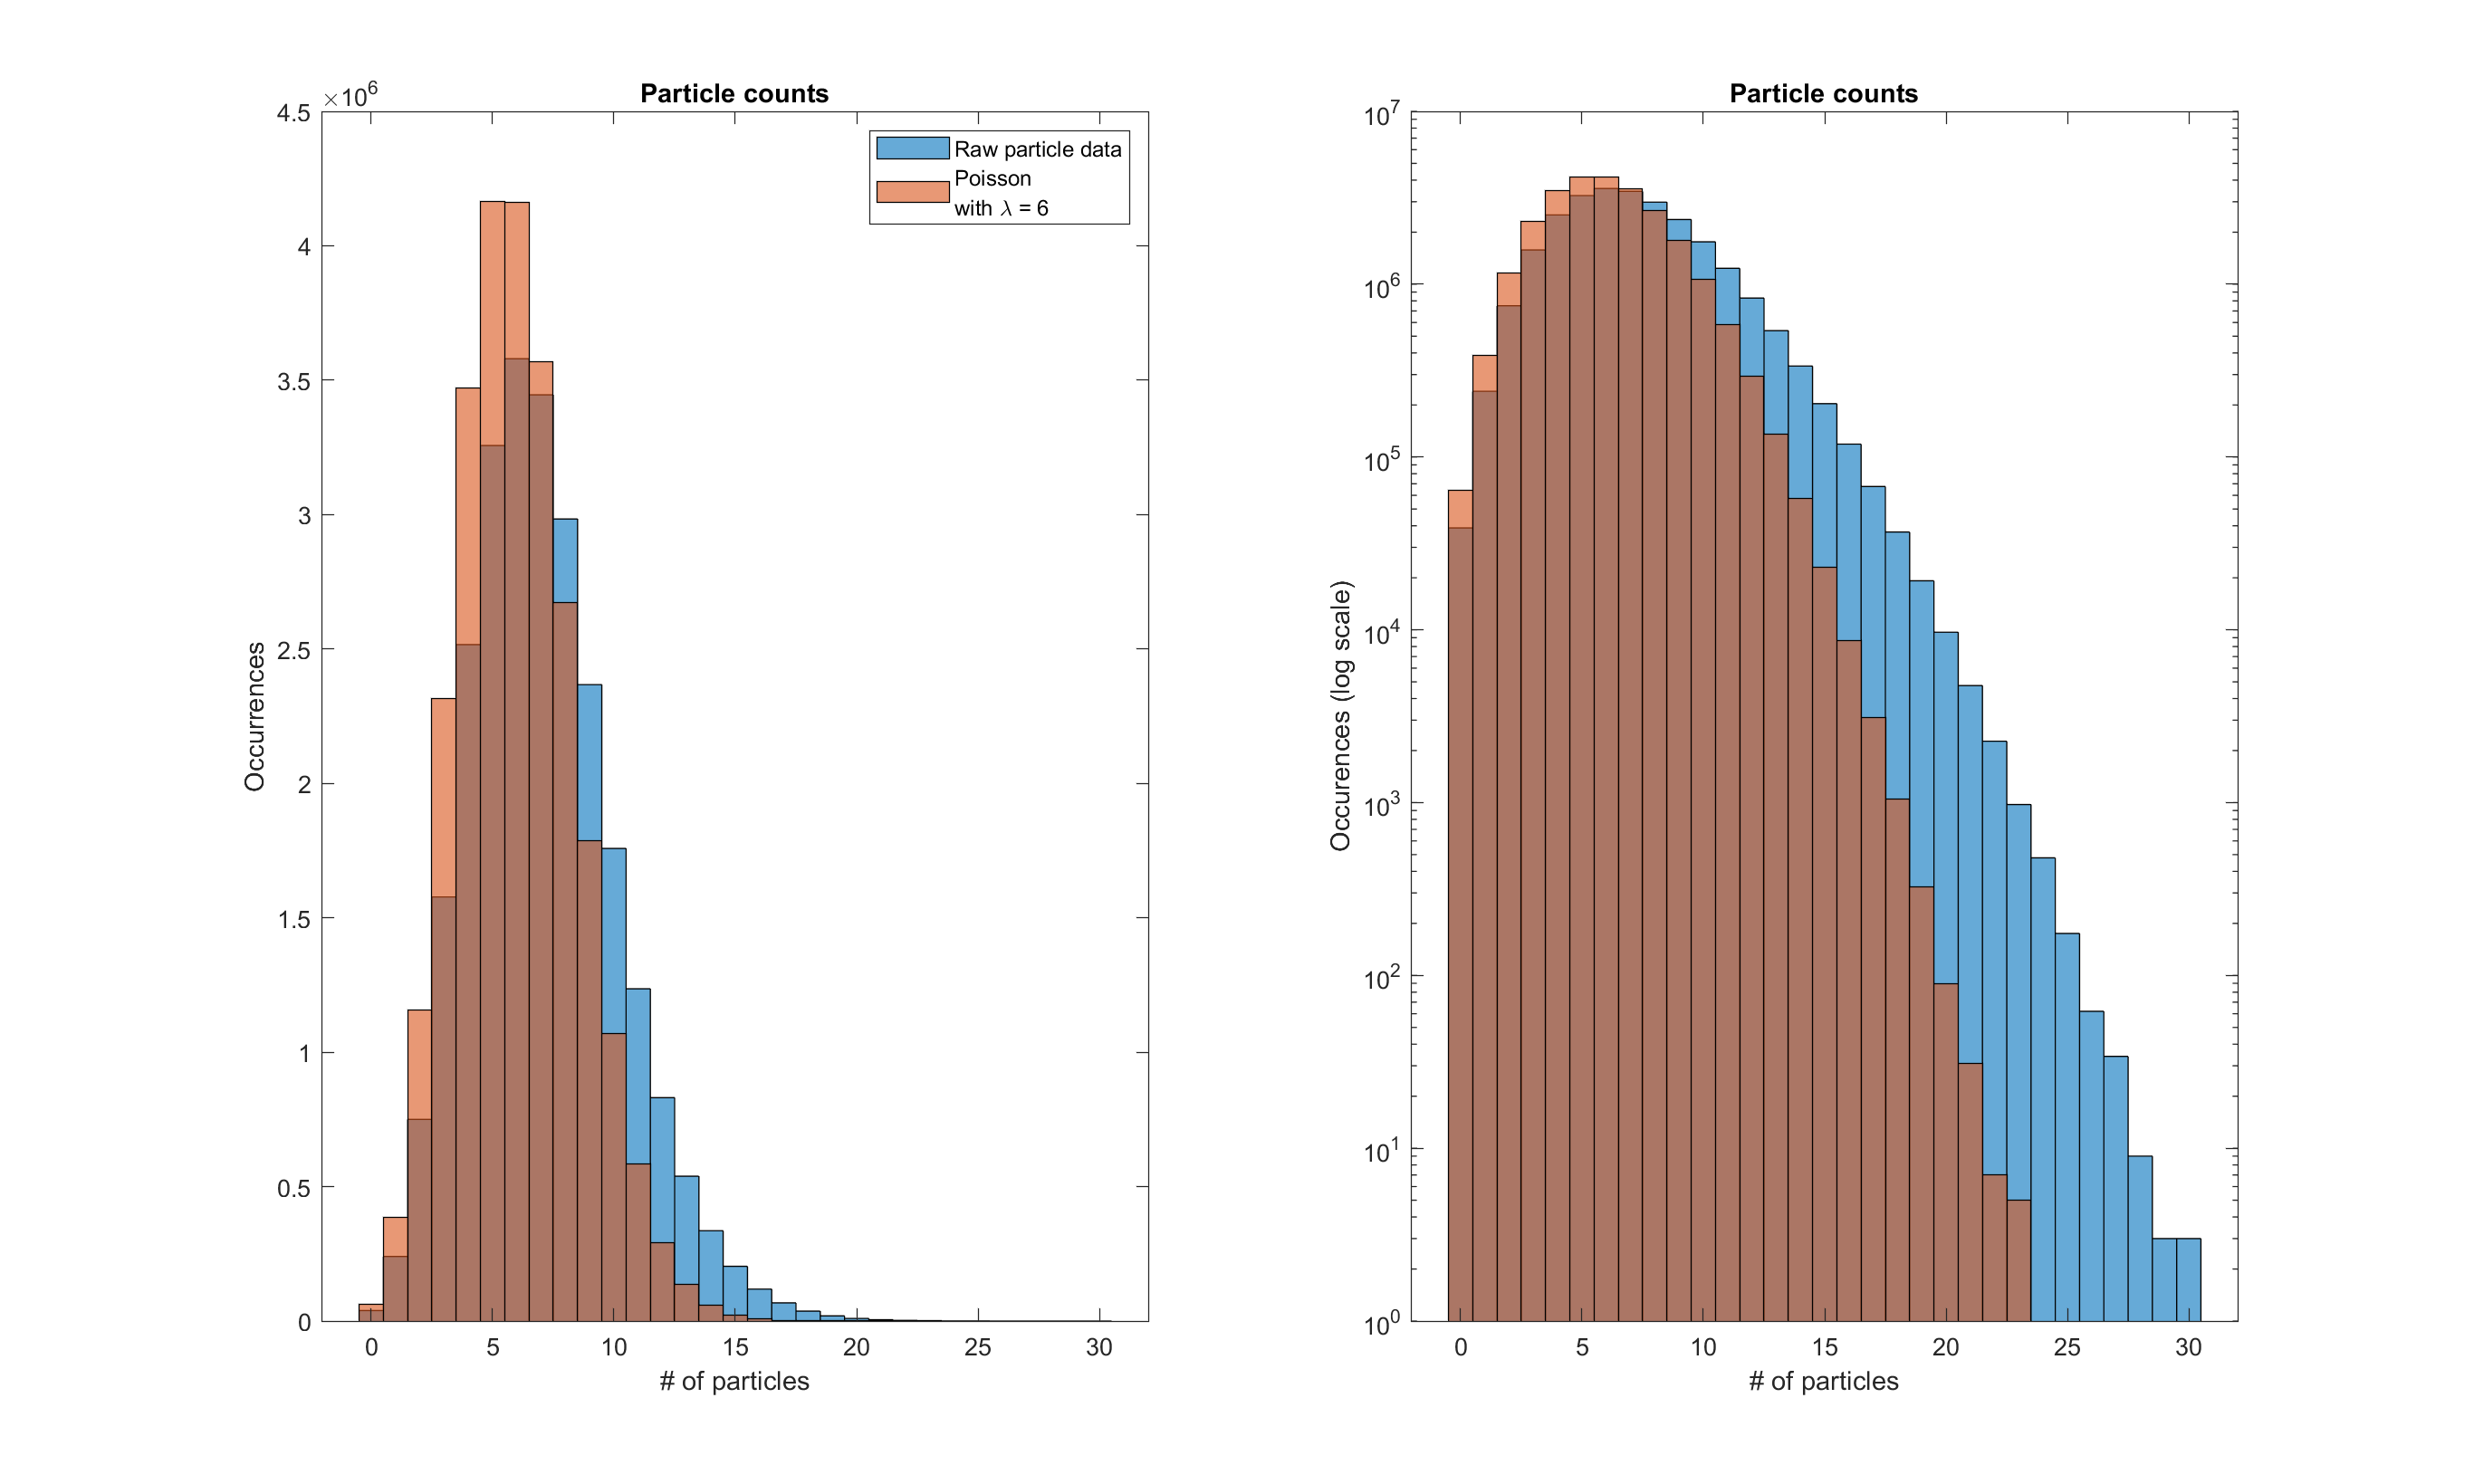

clf;
subplot(1, 2, 1)
histogram(particle_counts, 'BinMethod', 'Integers'), hold on;
poisson = makedist("Poisson", "lambda", 6);
poisson_vals = random(poisson, [1 length(particle_counts)]);
histogram(poisson_vals)
title('Particle counts');
xlabel('# of particles');
ylabel('Occurrences');
legend('Raw particle data', 'Poisson\newlinewith {\lambda} = 6');

subplot(1, 2, 2)
histogram(particle_counts, 'BinMethod', 'Integers'), hold on;
histogram(poisson_vals);
set(gca, 'YScale', 'log');
title('Particle counts');
xlabel('# of particles');
ylabel('Occurences (log scale)')

The data does **not** accurately follow a Poisson trend; rather, our data has far more measurements with high numbers of particles. 

Our current data does not accurately follow any particular distribution, and as such it is hard for us to perform statistical analysis on it. We would like to develop a model for the data that accounts for the anomalous region where the number of cosmic rays measured is very high. To do this, we can split the data into time intervals corresponding to times when the satellite is in the anomalous region and when it is not. 

Let's look again at the plot of particle counts over time and compare it to the plot of the Earth longitude over time. The system seems to exhibit anomalous behavior whenever the Earth longitude somewhere between 40 and 300 degrees. The most likely cause of this behavior may be the [South Atlantic Anomaly](https://en.wikipedia.org/wiki/South_Atlantic_Anomaly), a region of the Atlantic Ocean where the Earth's inner [Van Allen radiation belt](https://en.wikipedia.org/wiki/Van_Allen_radiation_belt) comes very close to the Earth's surface. As the Van Allen radiation belt is full of energetic charged particles, this region is known to cause several problems with satellites passing by, expecially particle counters such as the one we are currently investigating.

Assuming that this anomalous region is between 40 degrees and 300 degrees longitude:

normal_data_indices = (earth_longitude > 40) & (earth_longitude < 300);
anomalous_data_indices = ~normal_data_indices;
normal_counts = particle_counts(normal_data_indices);
normal_times = (times(normal_data_indices));
%Approximate the mean count # of the normal data
mean_normal = mean(normal_counts)

mean_normal = 6.4235

anomalous_counts = particle_counts(anomalous_data_indices);
anomalous_times = times(anomalous_data_indices);
%Approximate the mean count # of the anomalous data
mean_anomalous = mean(anomalous_counts)

mean_anomalous = 8.8490

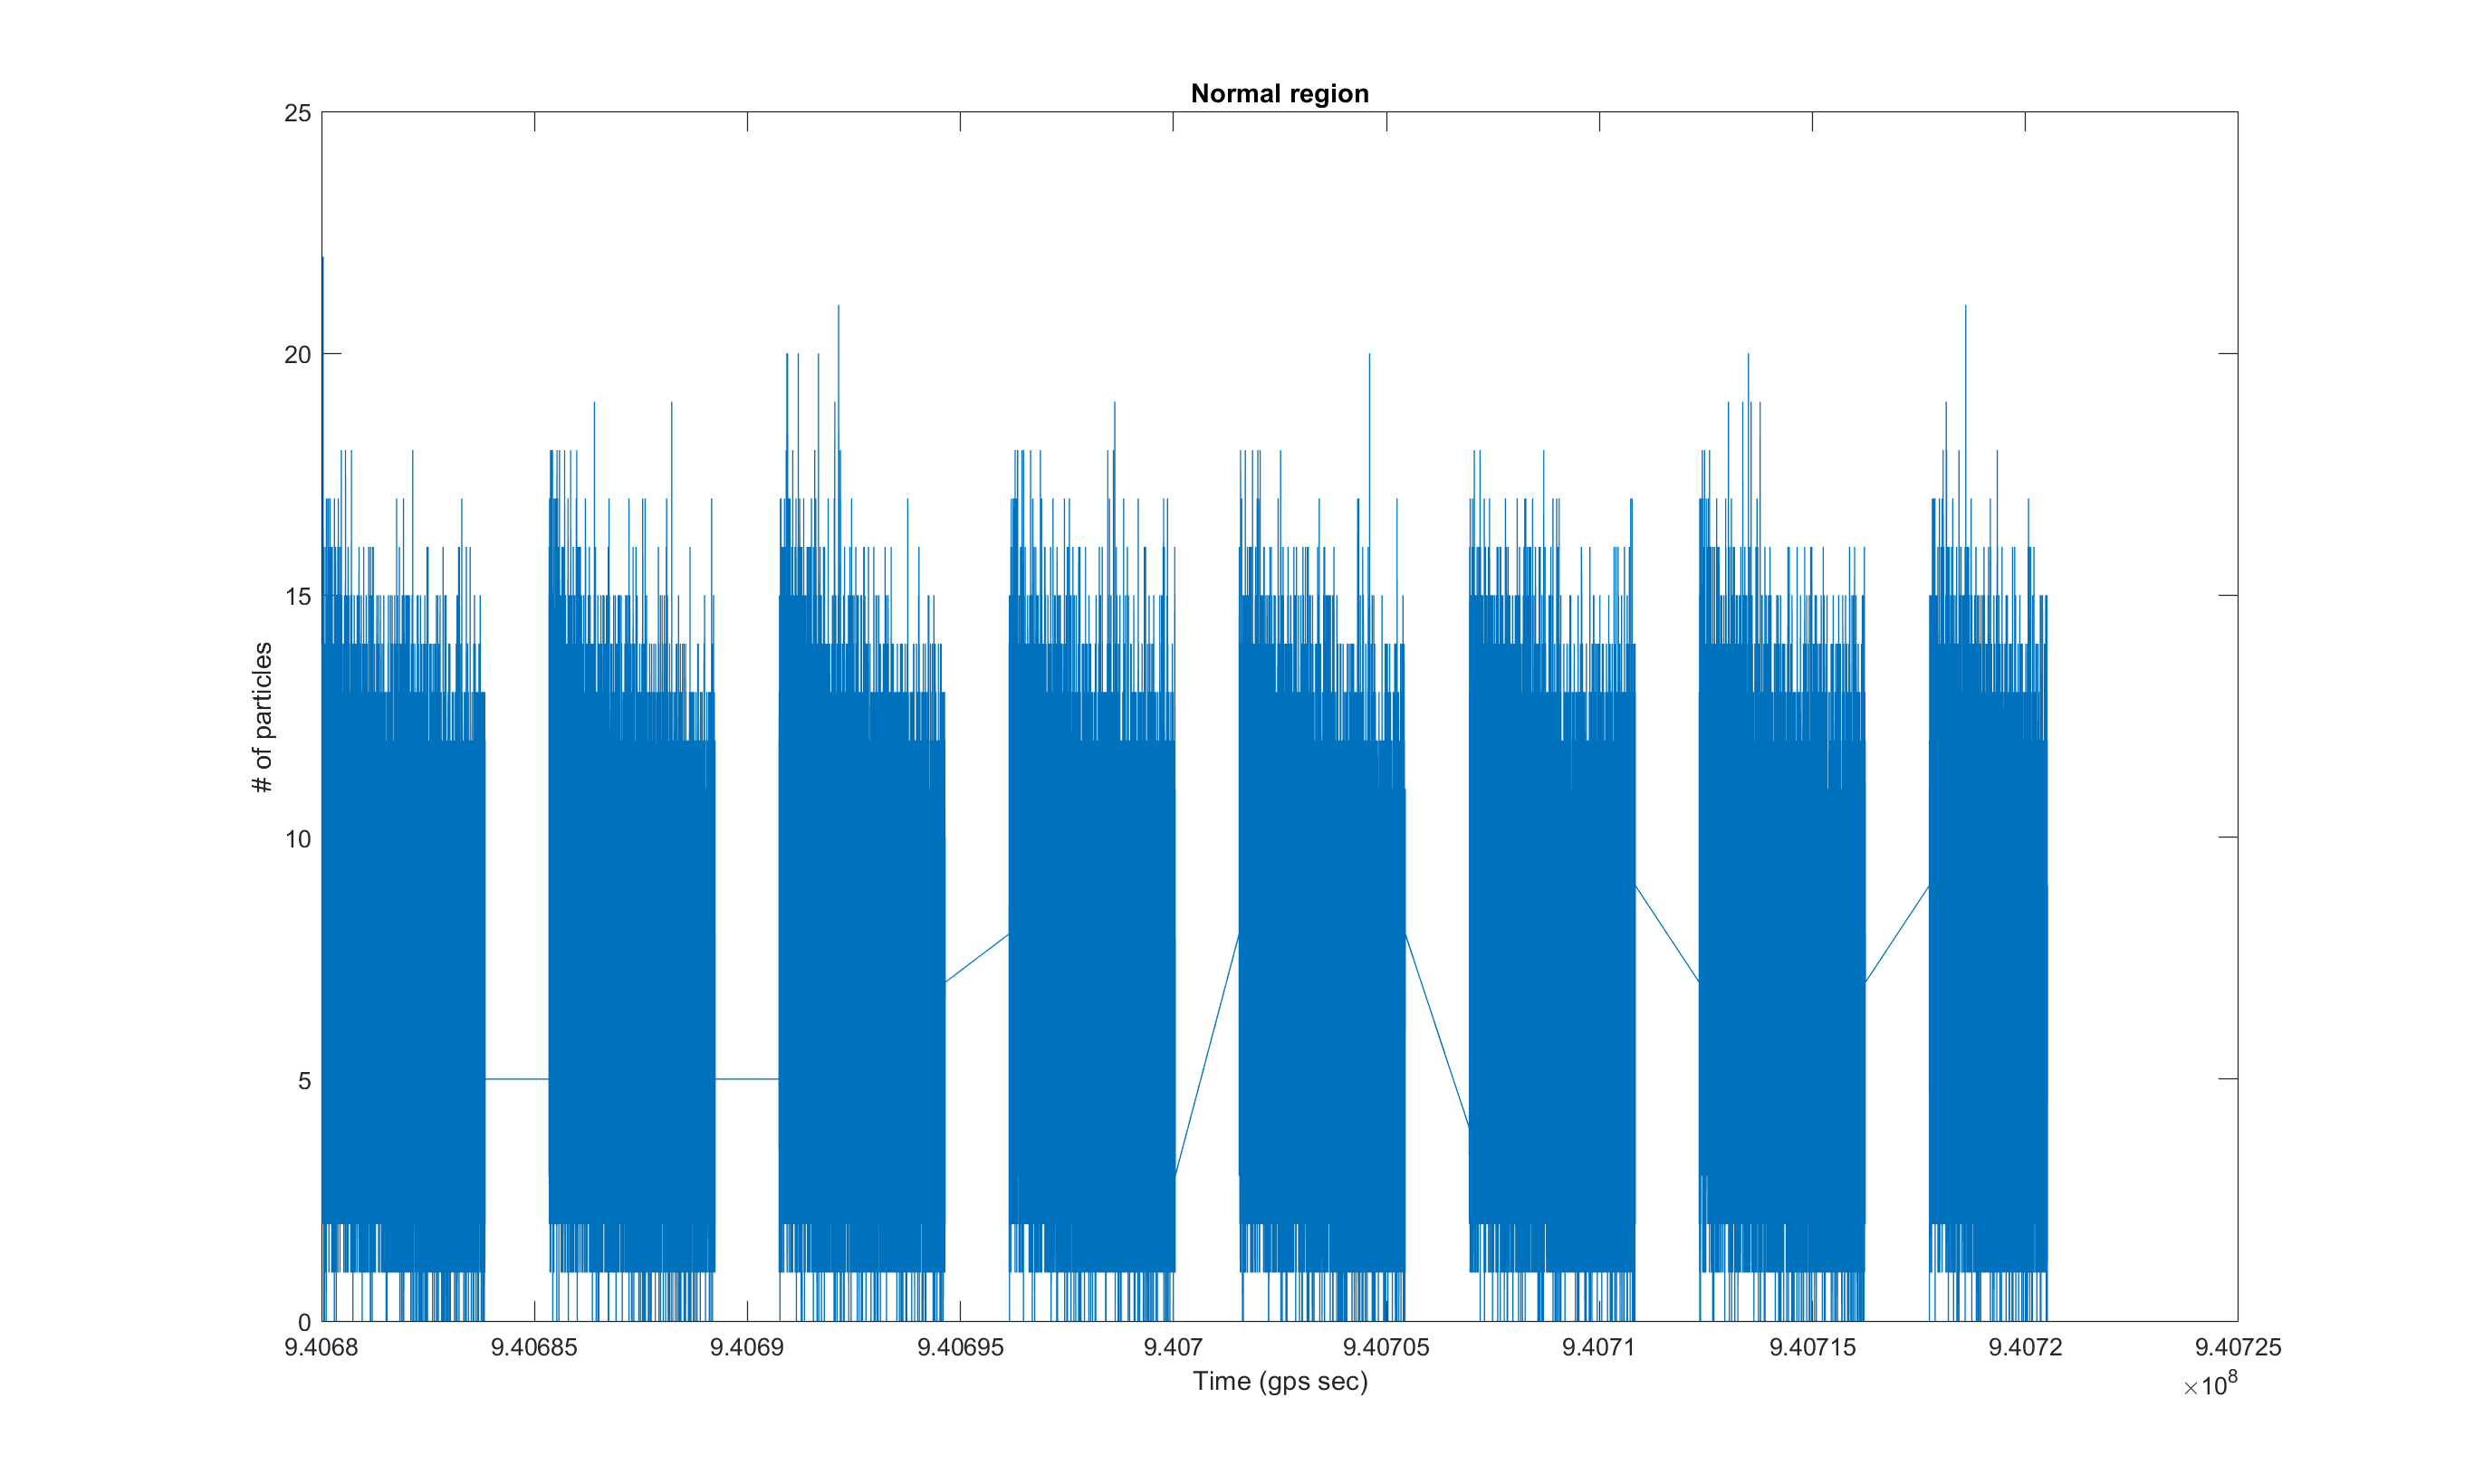

clf;
limit = 300000;
plot(normal_times(1:limit), normal_counts(1:limit));
title('Normal region');
xlabel('Time (gps sec)')
ylabel('# of particles')

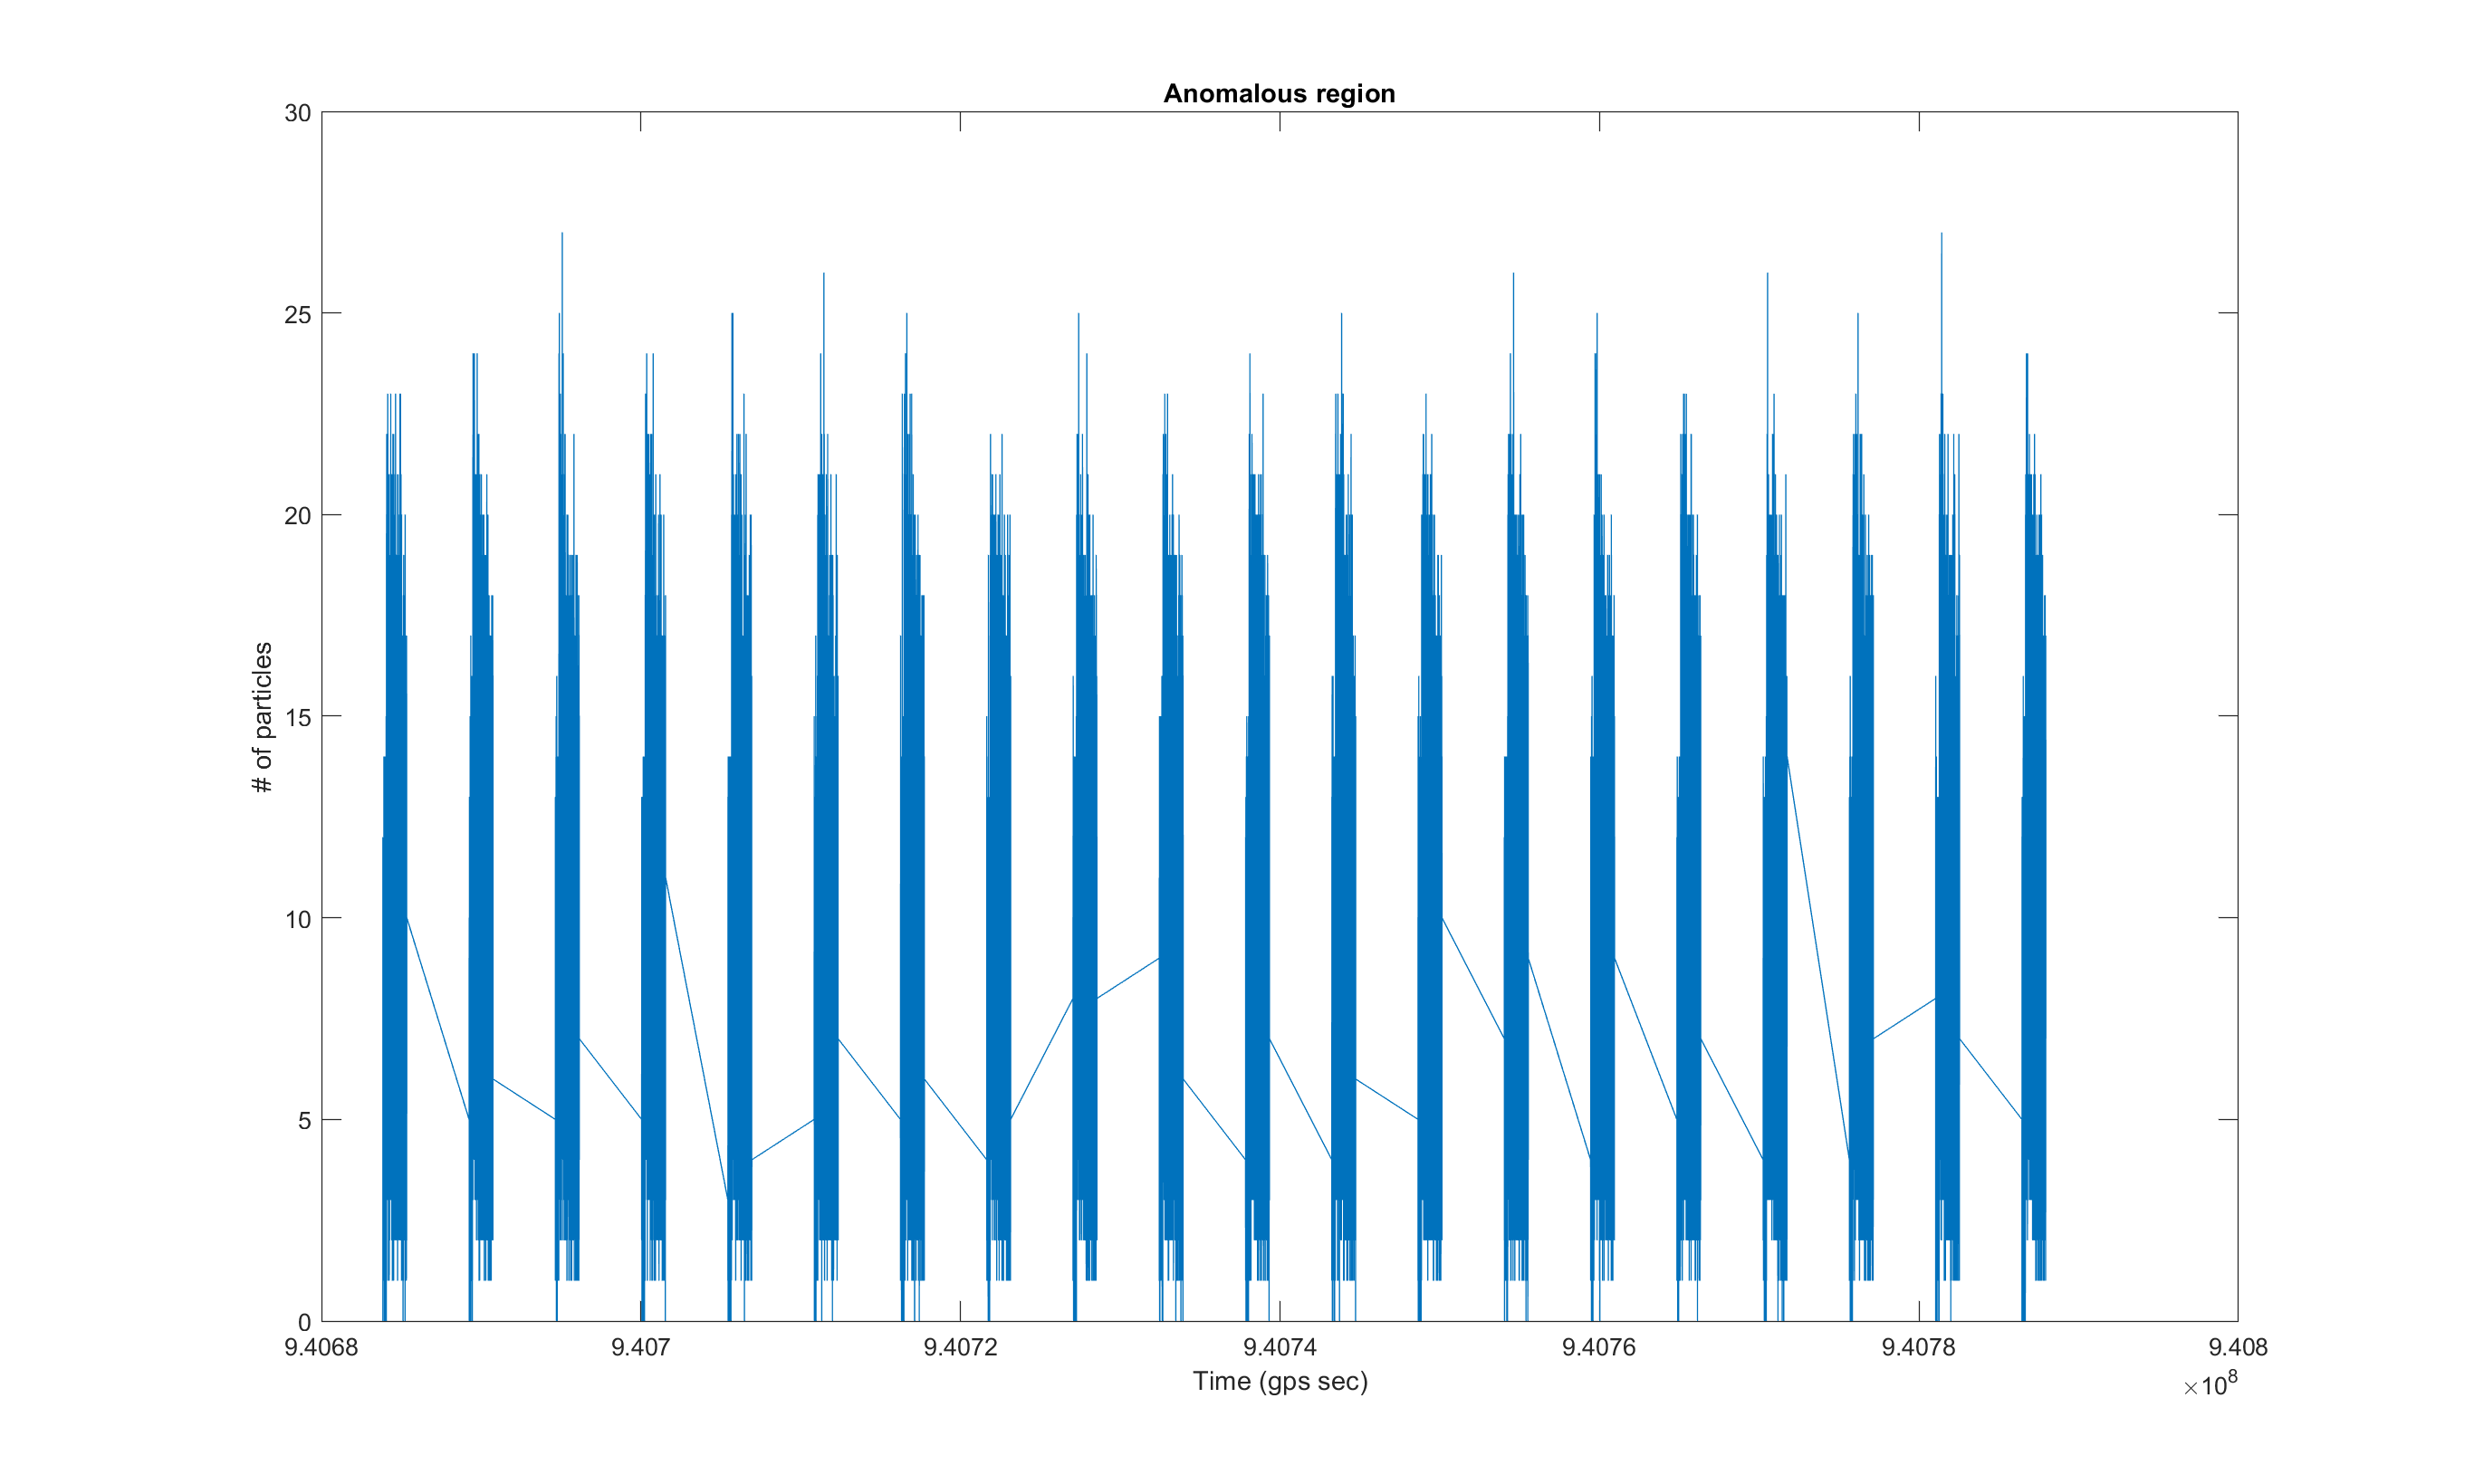

clf;
plot(anomalous_times(1:limit), anomalous_counts(1:limit));
title('Anomalous region');
xlabel('Time (gps sec)')
ylabel('# of particles')

Now that we have separated our data into two time-dependent data sets, we can model our data by switching between the anomalous and normal distributions depending on which region we are in. Each of these two distributions are more stable over time and vary less in the number of particles detected. Now we can model our distributions for the anomalous and normal regions with Poisson distributions:

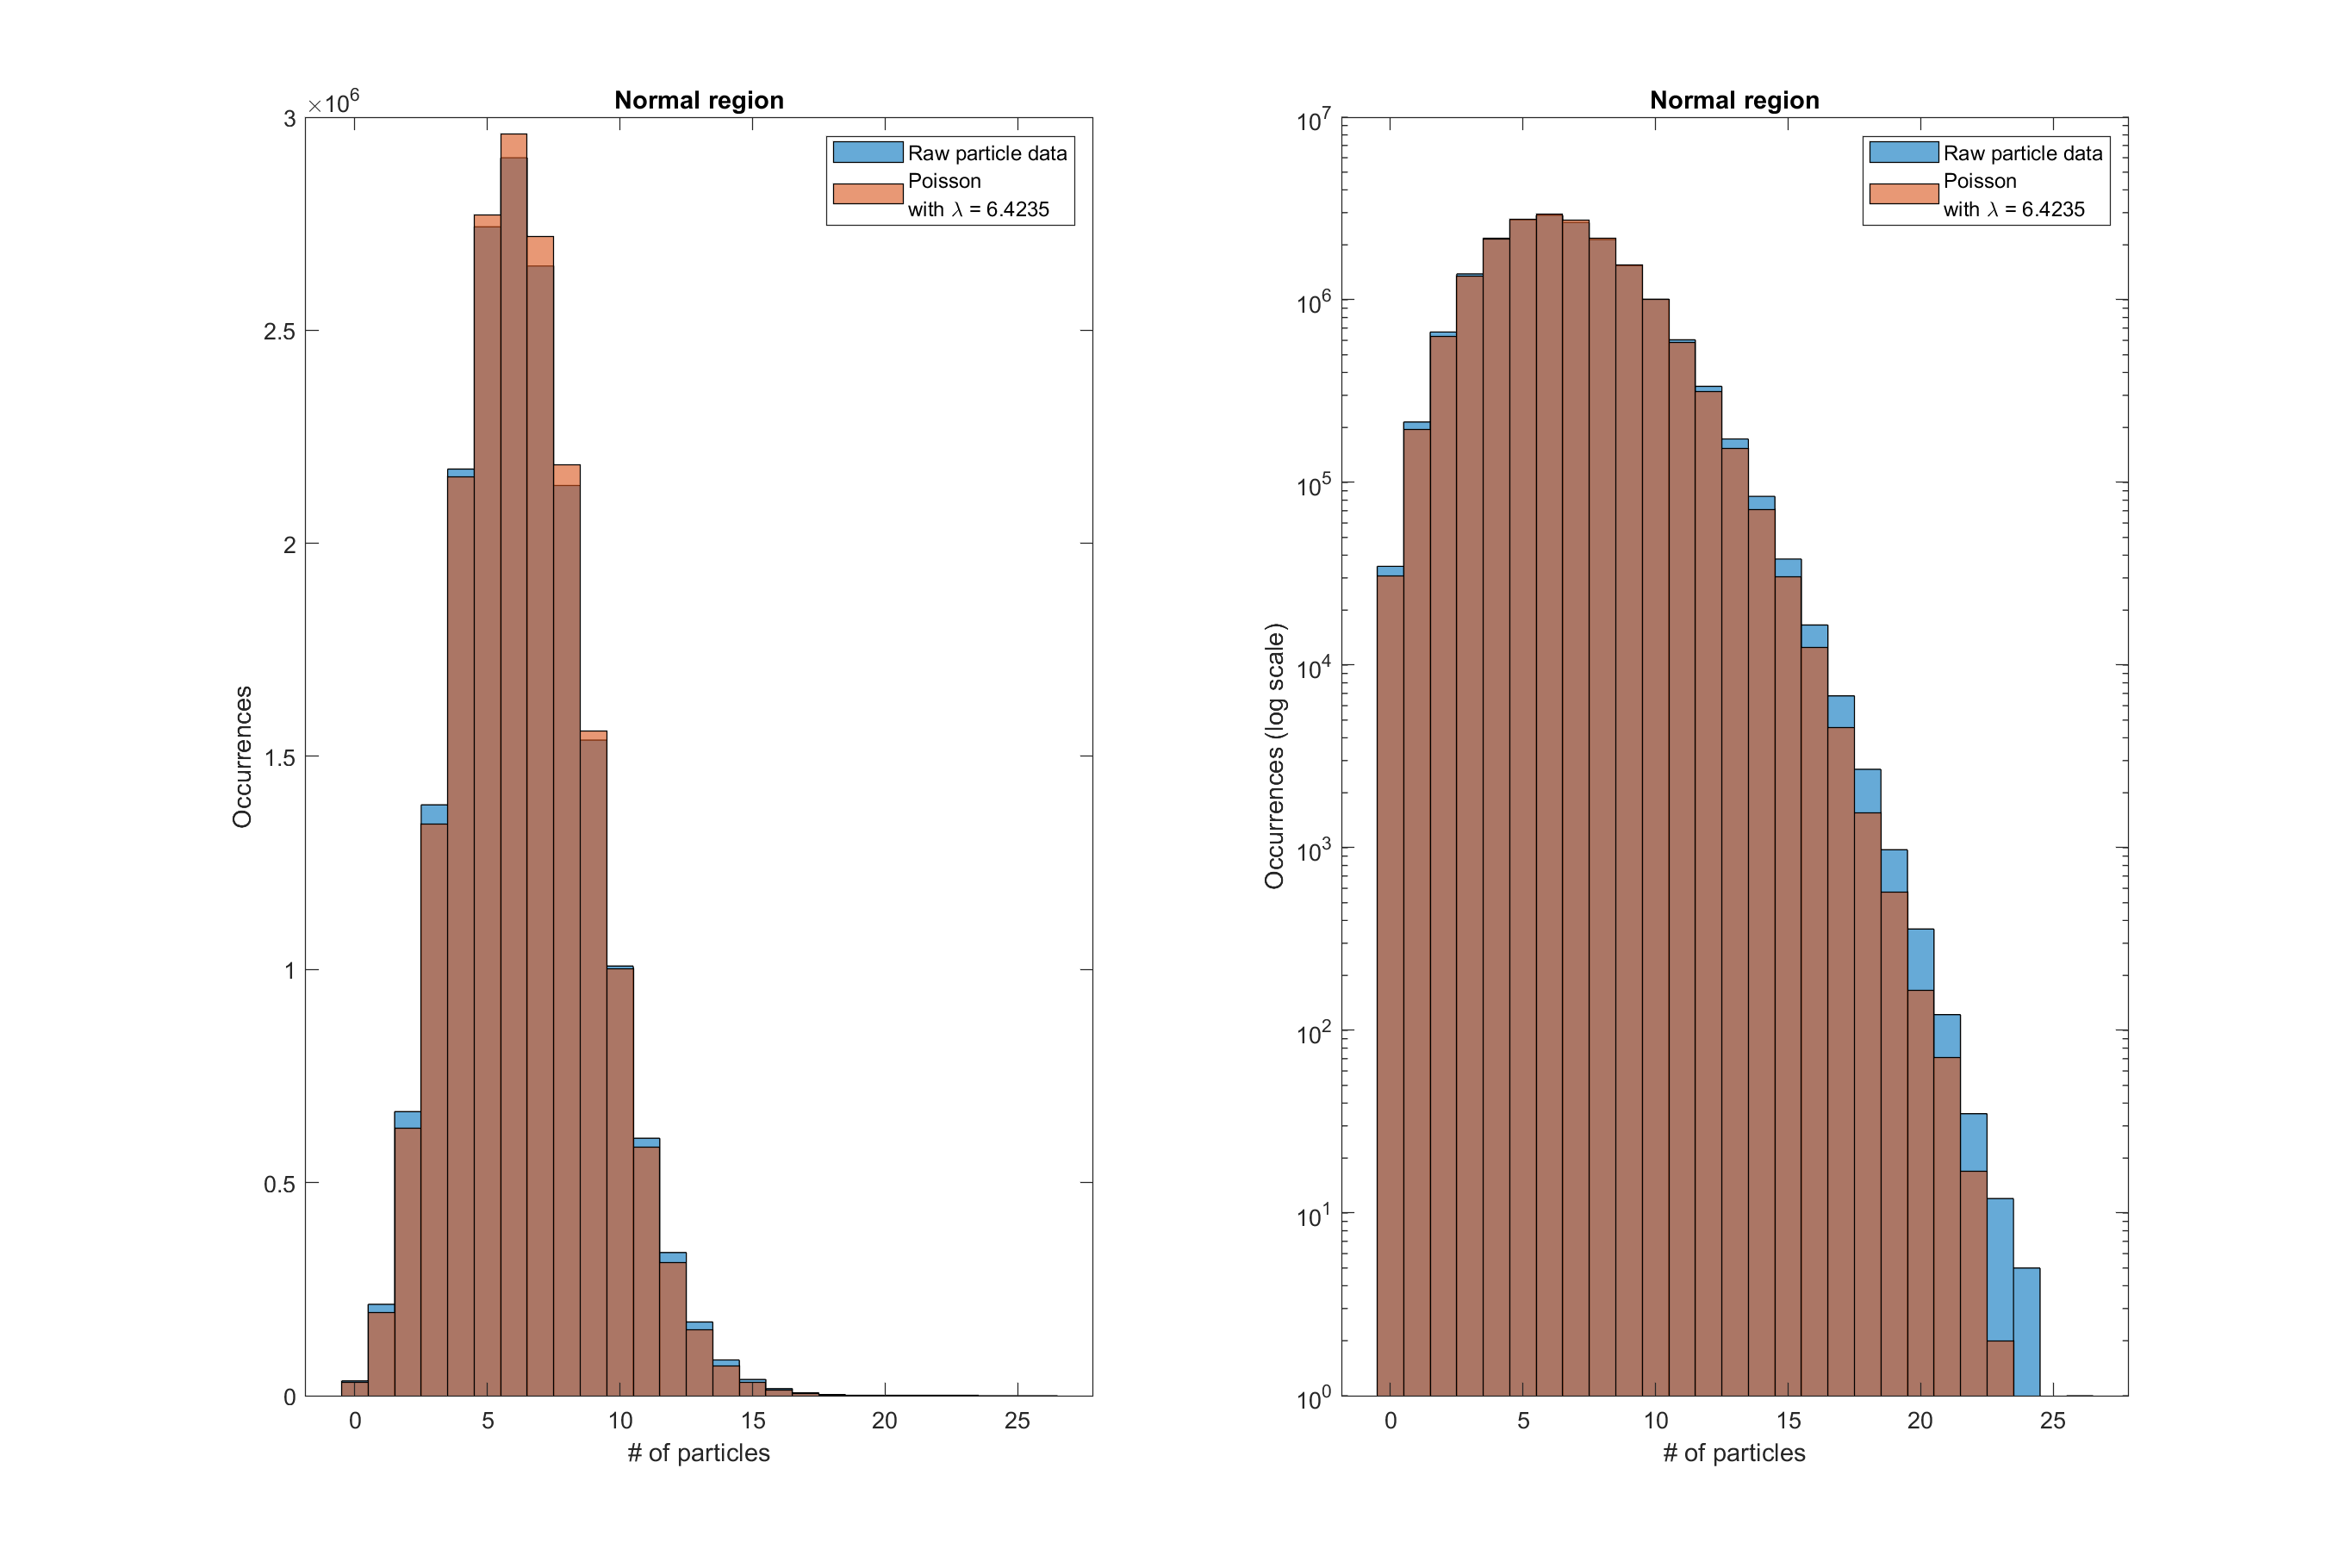

clf;
subplot(1, 2, 1)
histogram(normal_counts), hold on;
poisson = makedist("Poisson", "lambda", mean_normal);
poisson_vals = random(poisson, [1 length(normal_counts)]);
histogram(poisson_vals)
title('Normal region');
xlabel('# of particles');
ylabel('Occurrences');
legend('Raw particle data', ['Poisson\newlinewith {\lambda} = ' num2str(mean_normal)]);

subplot(1, 2, 2)
histogram(normal_counts), hold on;
histogram(poisson_vals)
set(gca, 'YScale', 'log');
title('Normal region');
xlabel('# of particles');
ylabel('Occurrences (log scale)');
legend('Raw particle data', ['Poisson\newlinewith {\lambda} = ' num2str(mean_normal)]);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);

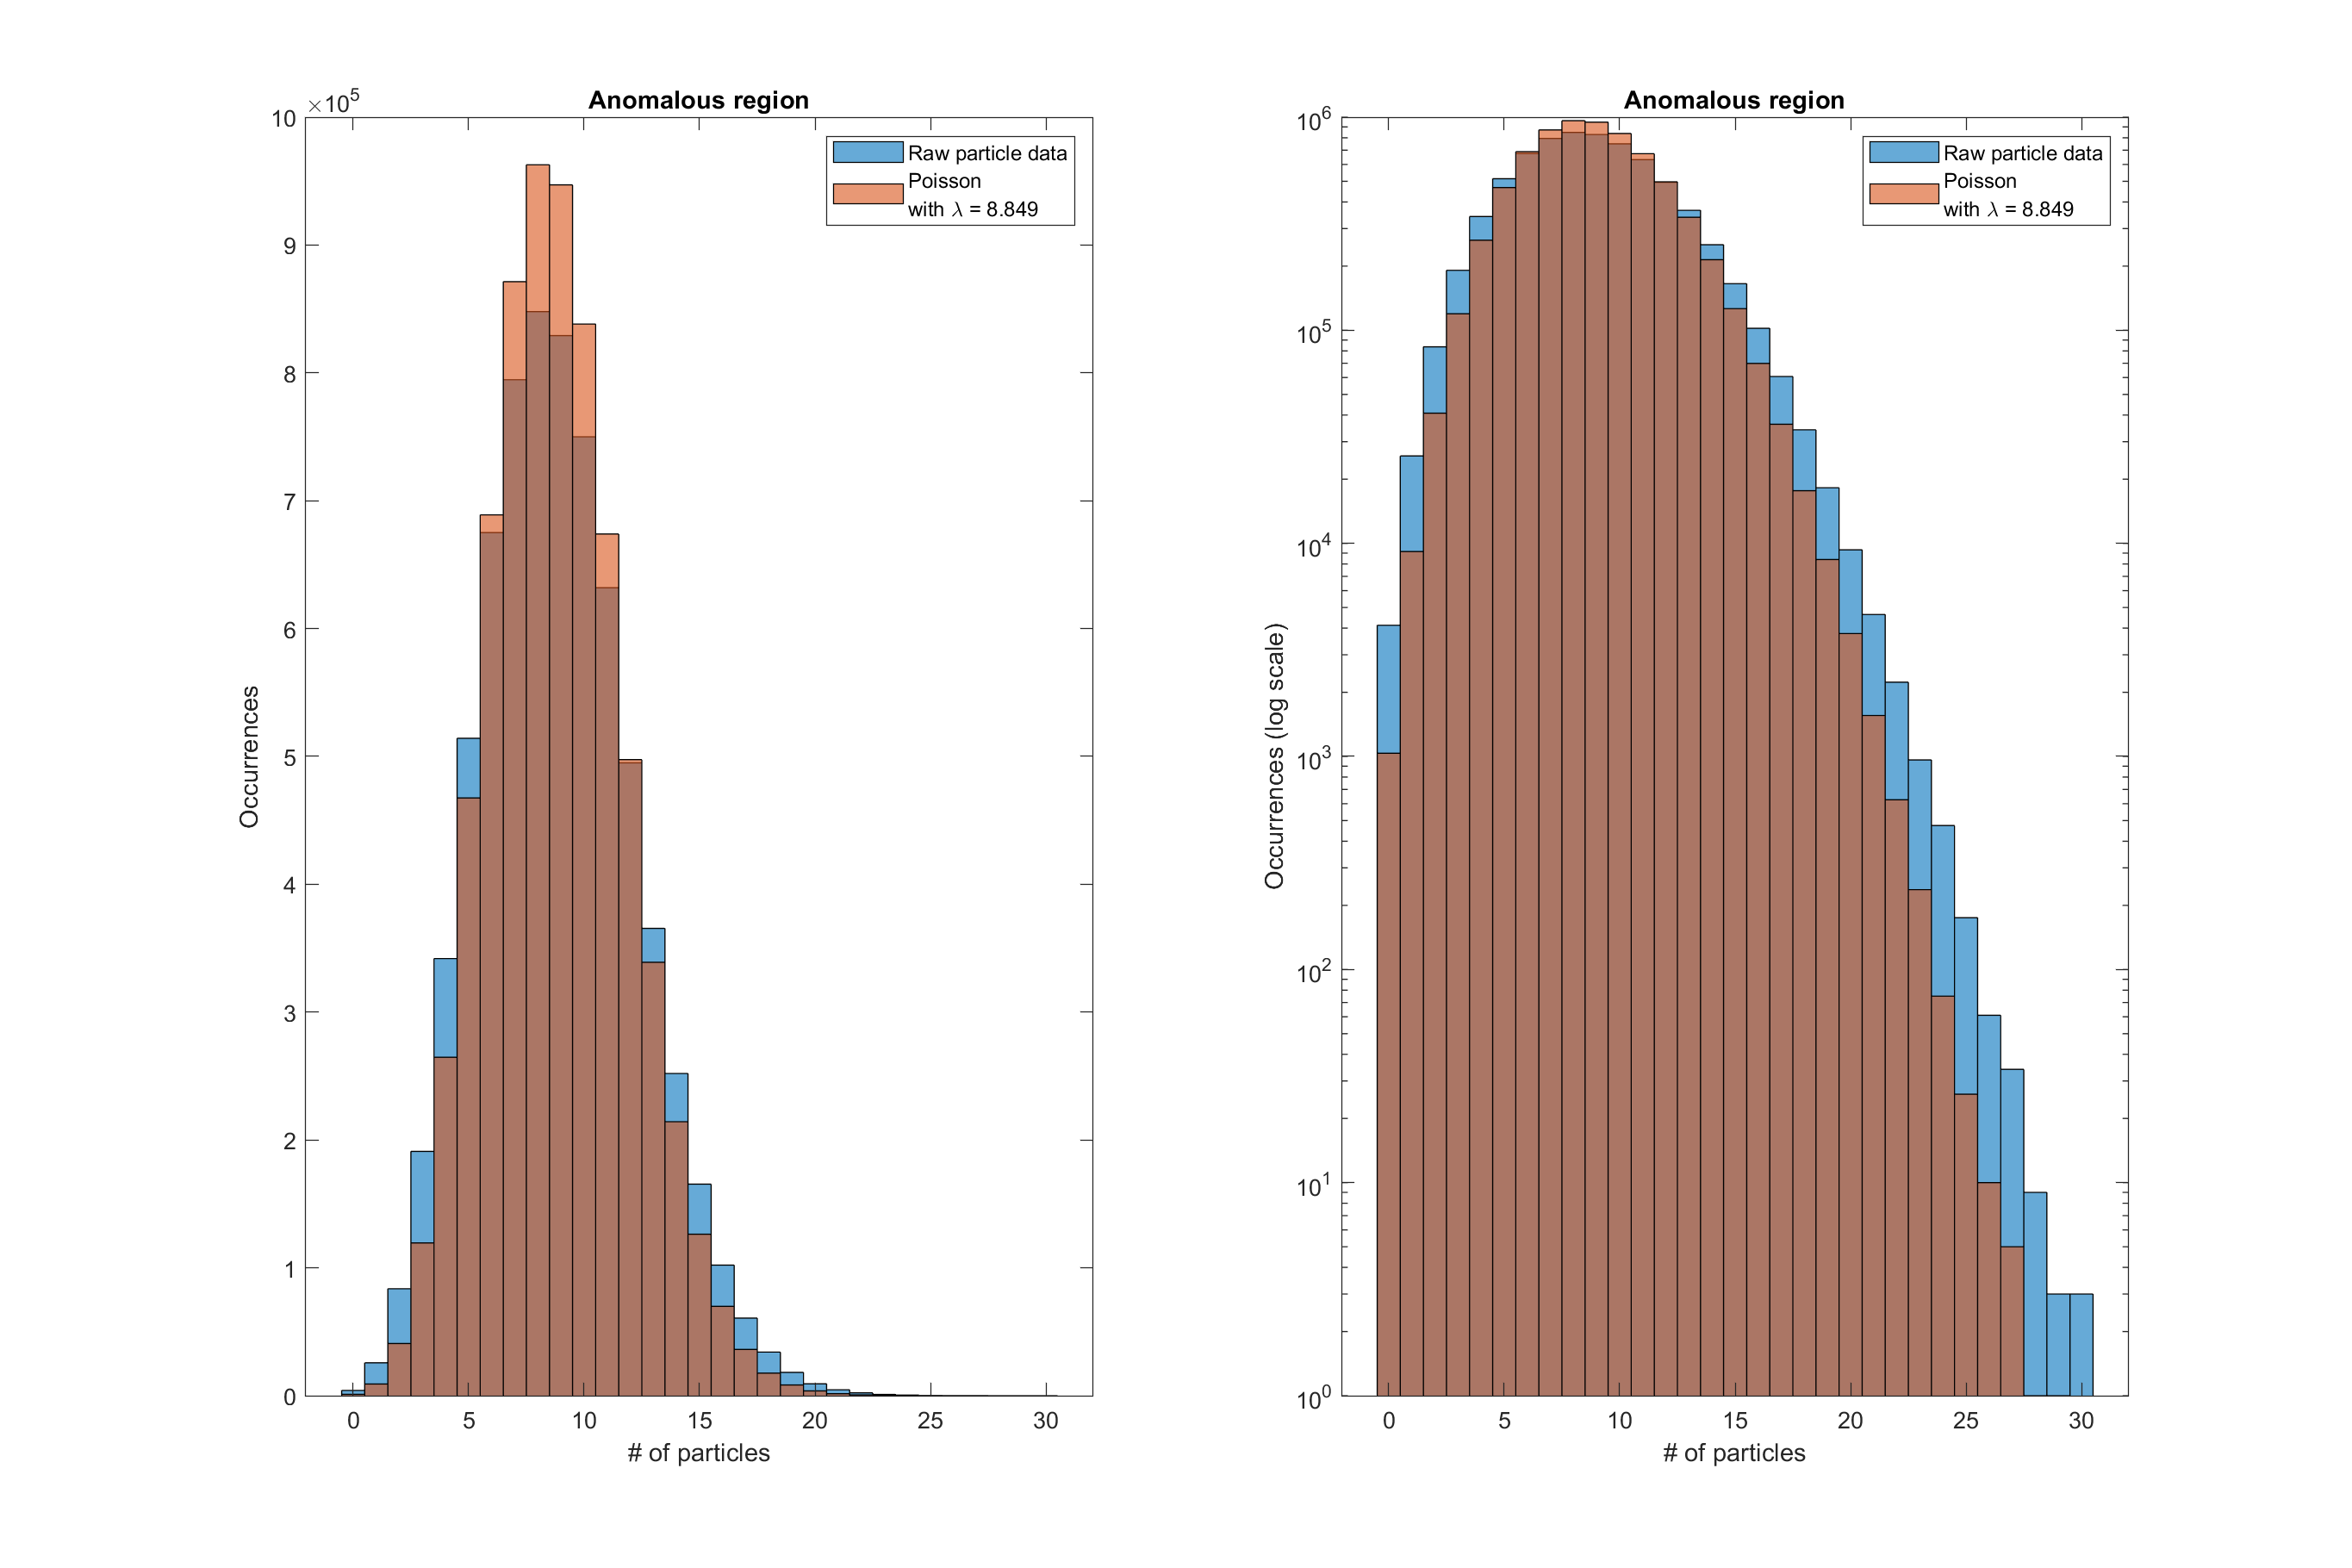

clf;
subplot(1, 2, 1)
histogram(anomalous_counts), hold on;
poisson = makedist("Poisson", "lambda", mean_anomalous);
poisson_vals = random(poisson, [1 length(anomalous_counts)]);
histogram(poisson_vals)
title('Anomalous region');
xlabel('# of particles');
ylabel('Occurrences');
legend('Raw particle data', ['Poisson\newlinewith {\lambda} = ' num2str(mean_anomalous)]);
subplot(1, 2, 2)
histogram(anomalous_counts), hold on;
histogram(poisson_vals)
set(gca, 'YScale', 'log')
title('Anomalous region');
xlabel('# of particles');
ylabel('Occurrences (log scale)');
legend('Raw particle data', ['Poisson\newlinewith {\lambda} = ' num2str(mean_anomalous)]);

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);

This is a much better representation of our data. By further tweaking the parameters of our Poisson model (i.e. changing the longitudes where the South Atlantic Anomaly begins and ends), one could make an even more accurate model of this data.

We would also like to investigate the quantity of particles that could be classified as a discovery in either region. In other words, we would like to answer the question: What is the number of particles you would need to see in 100 milliseconds such that it could be classified as a 5-sigma event? To do this, we use our Poisson models for each region and find the value of the cumulative distribution function (cdf) at a probability corresponding to a $5\sigma$ event on a normal distribution:

p_5sigma = normcdf(-5, 0, 1)

p_5sigma = 2.8665e-07

significant_particles_normal = abs(icdf('Poisson', 1-p_5sigma, mean_normal))

significant_particles_normal = 23

One would need to see 23 particles in 100 milliseconds inside the normal region to claim a $5\sigma$ discovery.

significant_particles_anomalous = abs(icdf('Poisson', 1-p_5sigma, mean_anomalous))

significant_particles_anomalous = 27

One would need to see 27 particles in 100 milliseconds inside the anomalous region to claim a $5\sigma$ discovery. This number is higher than the number required in the normal region since the Van Allen belt contributes to the background, creating more noise in the signal.

### Problem 2

Here we will be observing a set of 10 images of the night sky.

clear;
h5disp("images.h5");

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


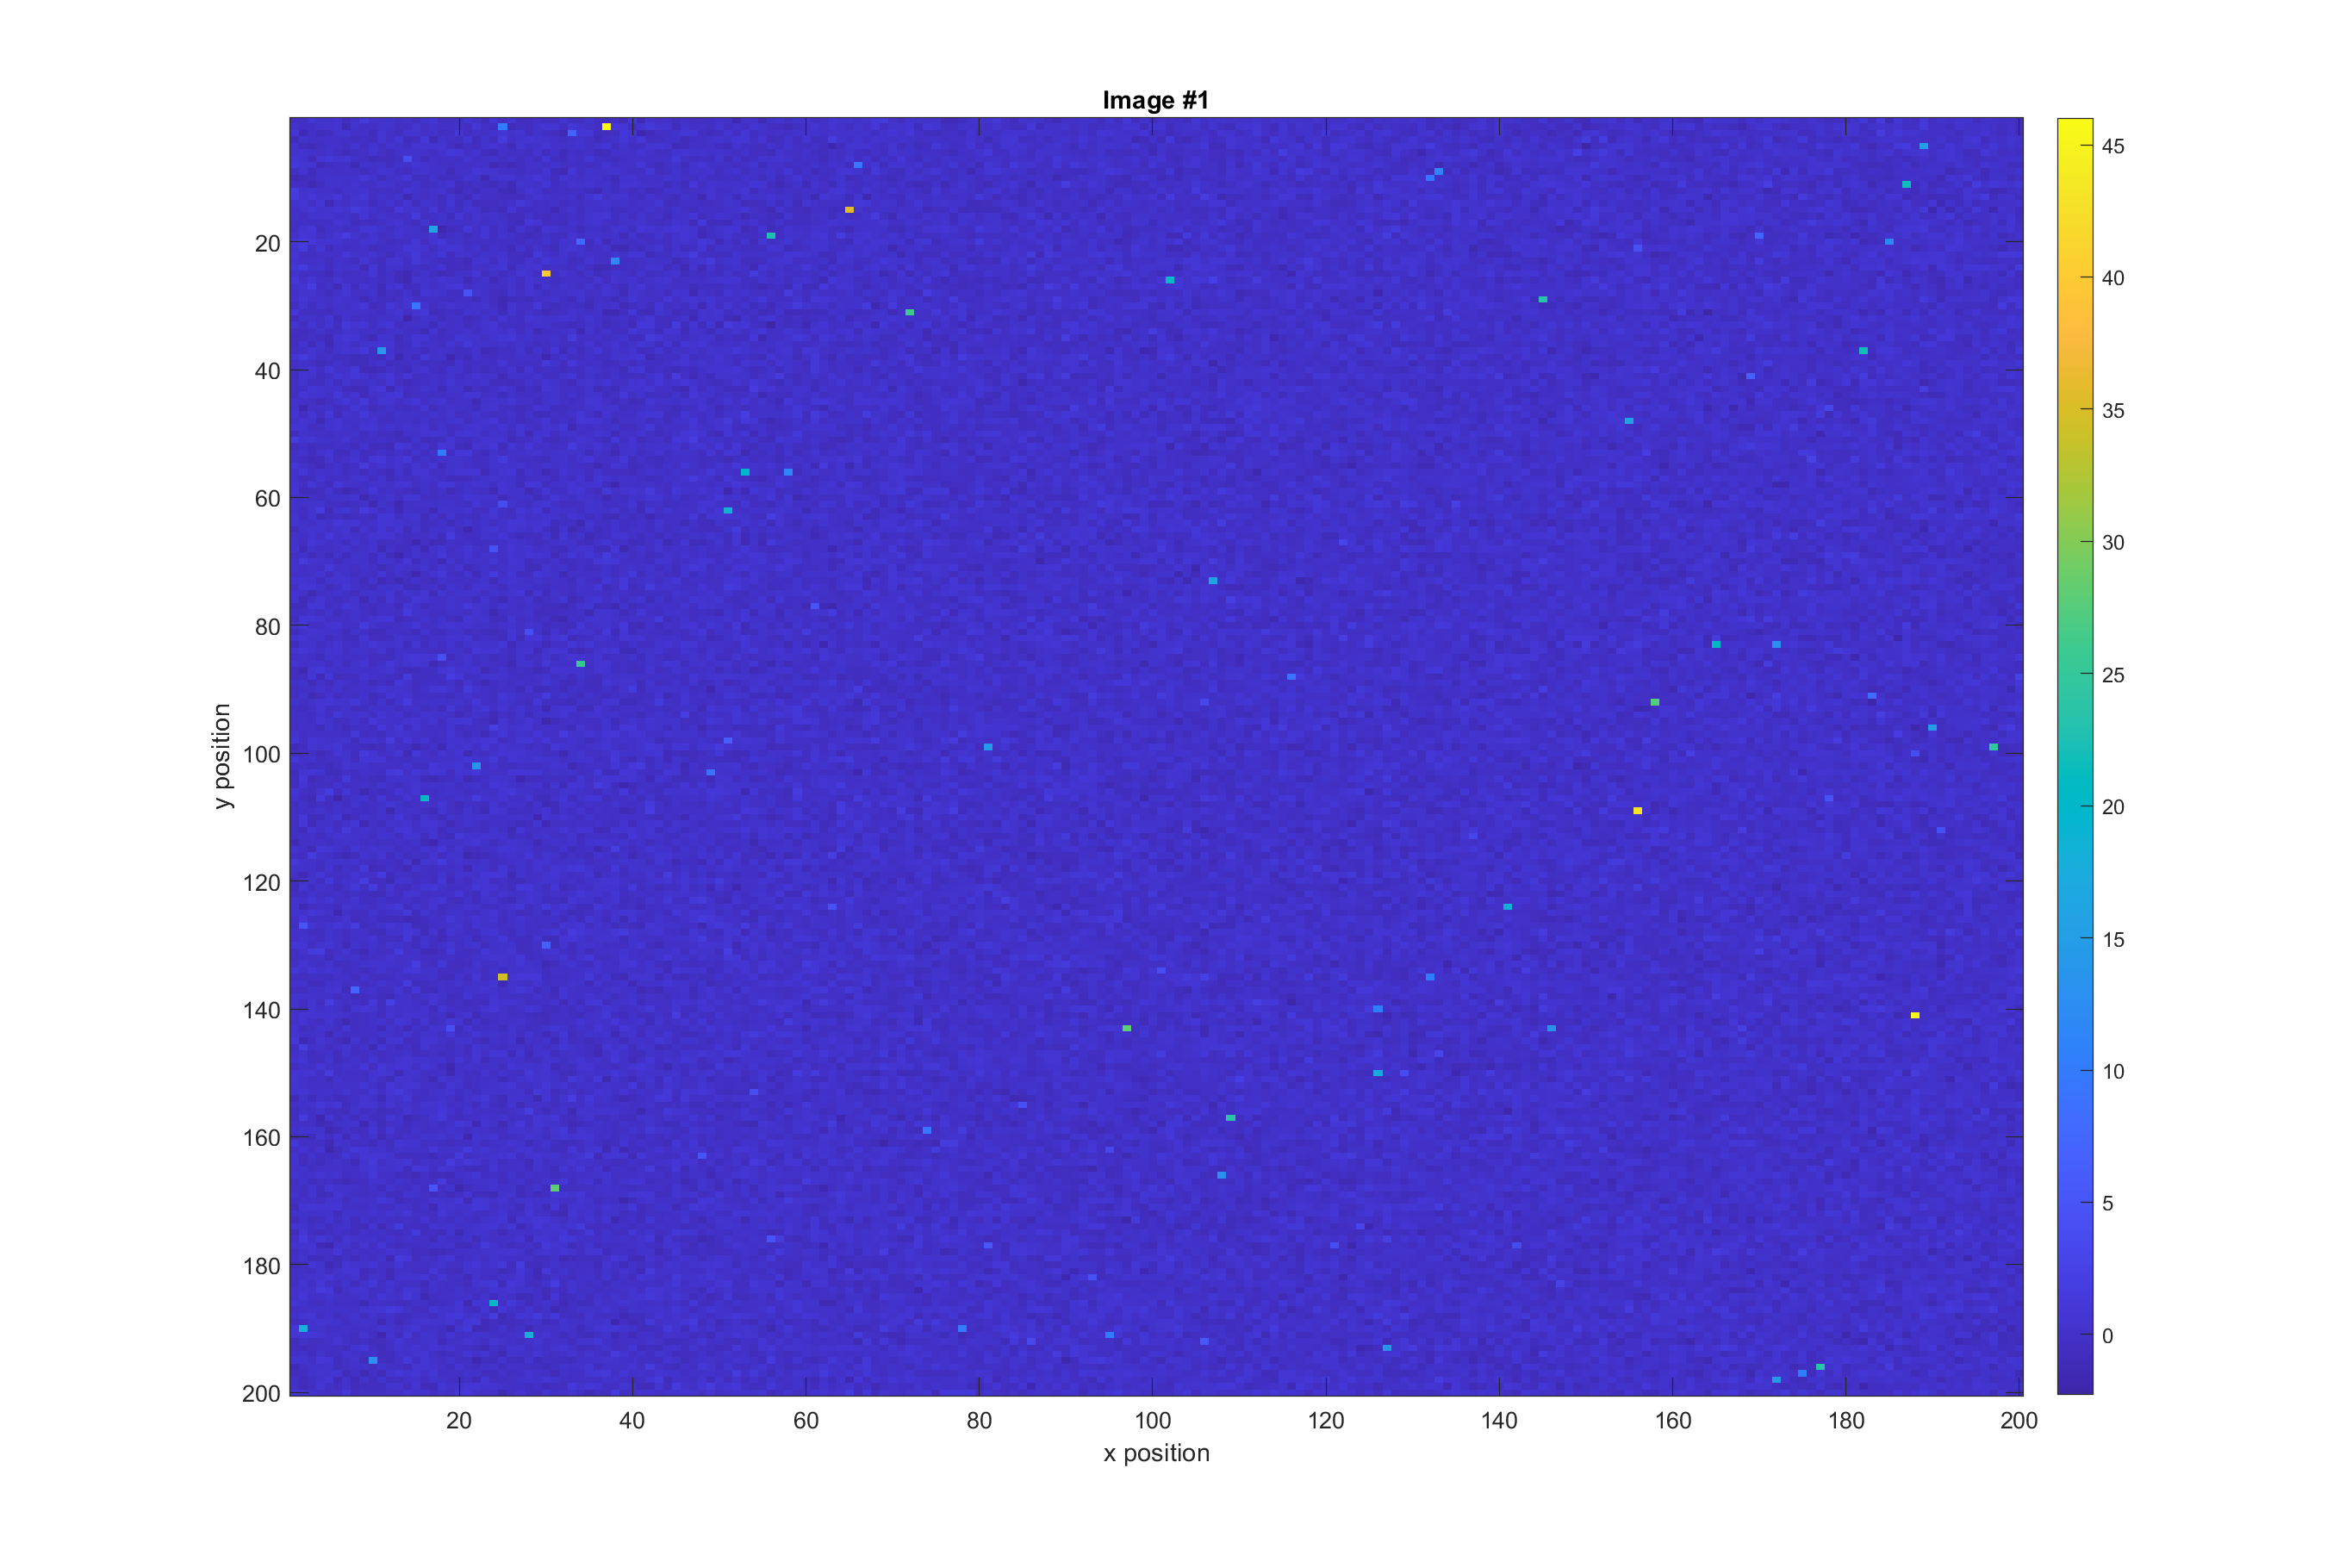

mydata = h5read("images.h5",'/imagestack');

clf;
image1 = squeeze(mydata(1, :, :));
imagesc(image1);
c = colorbar;
title('Image #1');
xlabel('x position');
ylabel('y position');

This is the data from one image visually represented by various colors. This picture shows us the brightness of pixels relative to a baseline brightness $B_0$. We will set $B_0 =0$.

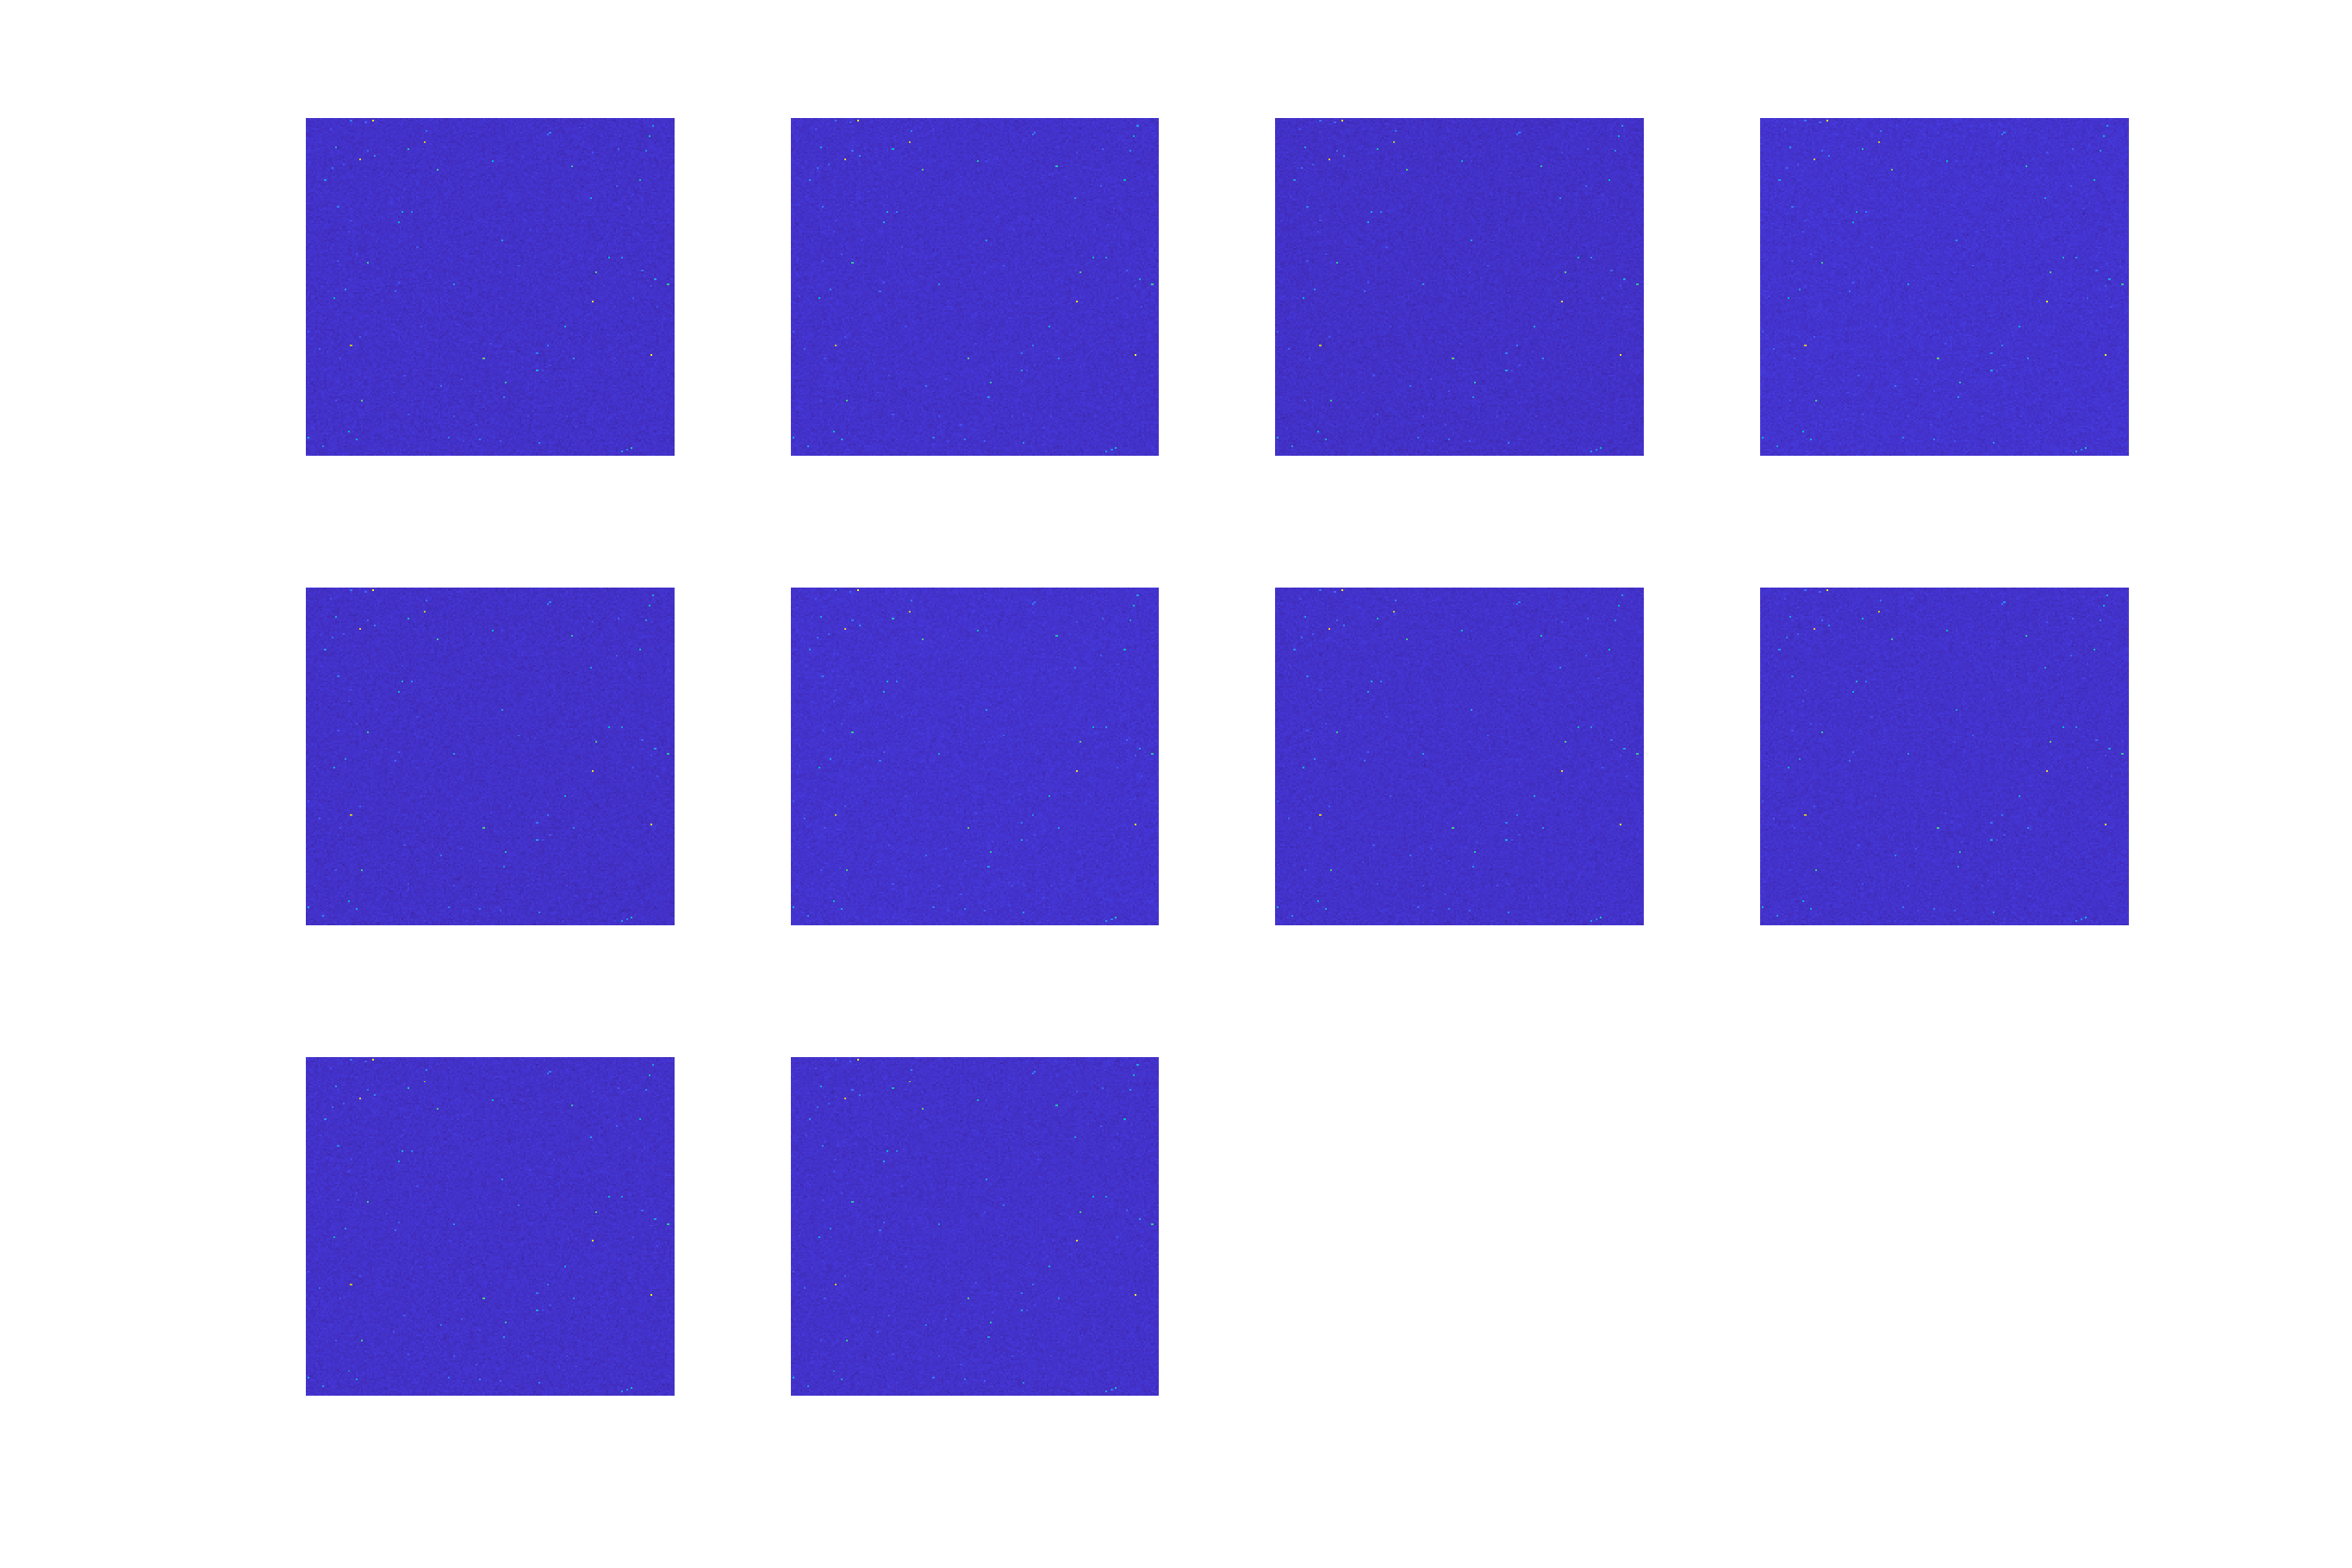

clf;
for ii = 1:10
    subplot(3, 4, ii);
    imagesc(squeeze(mydata(ii, :, :)));
    set(gca, 'visible', 'off')
end

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);

First let us establish the distribution of the background for this data, as well as establish what counts as a significant event.

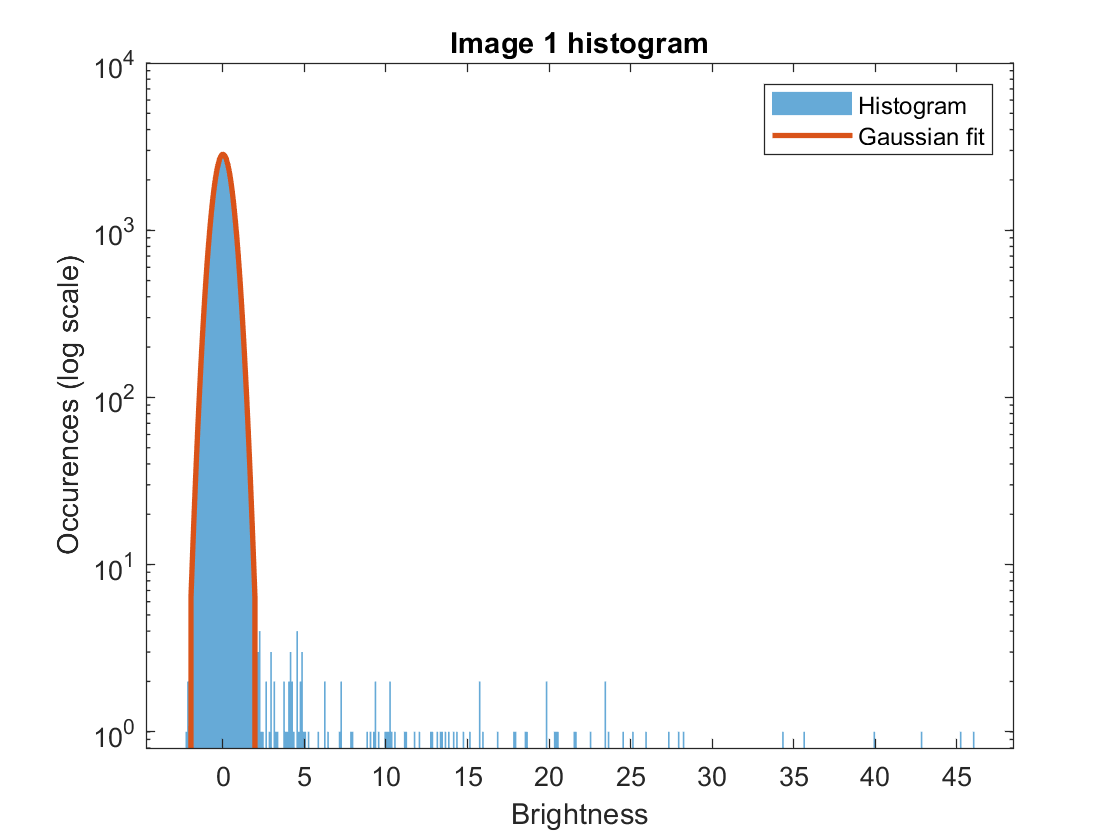

clf;

%%include spatial dependence and time dependence%%

histogram(image1, 'edgecolor', 'none'), hold on;
set(gca, 'YScale', 'log')
%find profile of background
bkg1 = image1(image1 < 2);
mean_bkg1 = 0;
std_bkg1 = std(bkg1);
xs = linspace(-2, 2, 100);
ys = normpdf(xs, mean_bkg1, std_bkg1) .* 4e3;
ys(1) = 1e-20;
ys(end) = 1e-20;
plot(xs, ys, 'Linewidth', 2)
ylim([.8 1e4])
title('Image 1 histogram');
xlabel('Brightness');
ylabel("Occurences (log scale)")
legend('Histogram', 'Gaussian fit');

The background of this data seems approximately Gaussian, as shown by the Gaussian fit curve in red. By removing the background, we can plot only the stars in our data.

We should consider anything with a brightness greater than $5\sigma$ away from the mean to be significant. So, we remove everything less than $5\sigma$ from the distribution:

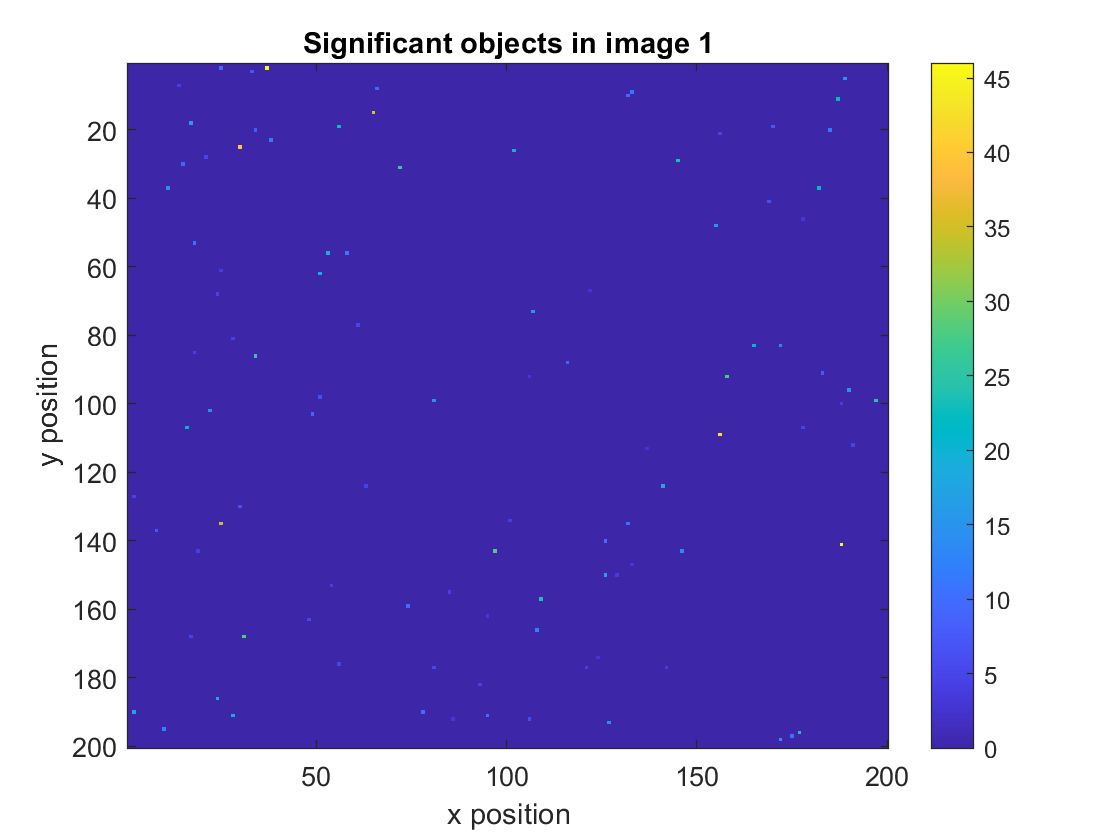

%plot only significant events:

clf;
image1_stars = image1 .* (image1 > 5*std_bkg1 | image1 < -5*std_bkg1);
imagesc(image1_stars)
colorbar
title('Significant objects in image 1')
xlabel('x position');
ylabel('y position');

The background looks much cleaner. 

We are interested in finding the differences between images - transients, or objects which are different or absent from one image to another. When adding two normal distributions together, the sum will be a normal distribution with $\mu =\mu_1 +\mu_2$ and standard deviation $\sigma =\sqrt{\sigma_1^2 +\sigma_2^2 }$. Since the mean of images 1 and 2 are both 0, and they have very similar values of sigma (they are nearly identical images), we can try subtracting the data from one image to another. This process (which is summing one distribution with another that has been multiplied by -1) will yield another normally distributed background with $\mu =0$ and $\sigma =$ $\sqrt{2{\sigma_1 }^2 }=\sqrt{2}\sigma_1$.

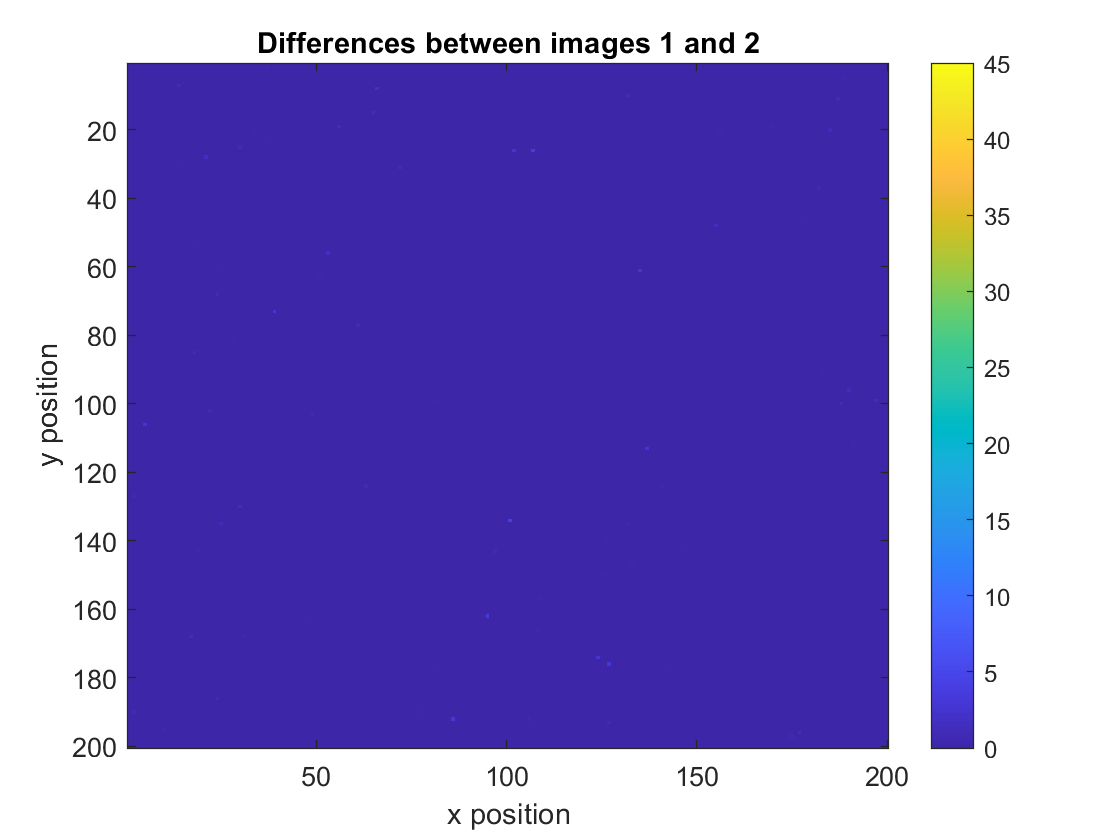

clf;
objectdata1 = objectfilter(image1);
objectdata2 = objectfilter(squeeze(mydata(2, :, :)));
objectdata1_2 = objectdata2 - objectdata1;
clf;
imagesc(abs(objectdata1_2));
colorbar;
caxis([0 45]);
title('Differences between images 1 and 2')
xlabel('x position');
ylabel('y position');

There is clearly very little variation between images 1 and 2. If we scale the colors accordingly so we can more easily observe the positions of the different objects:

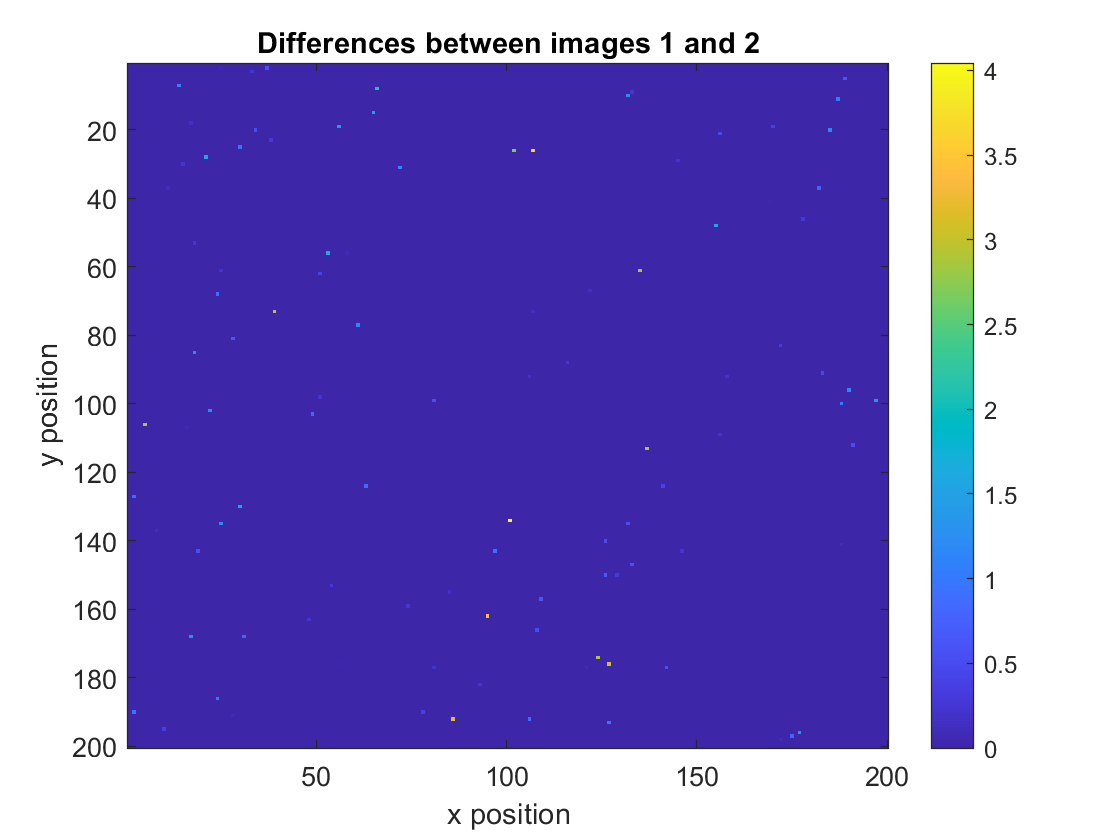

clf;
imagesc(abs(objectdata1_2));
colorbar;
title('Differences between images 1 and 2')
xlabel('x position');
ylabel('y position');

There are some data points that do not match the relative positions of obvious stars from images 1 and 2, which may correspond to possible outliers from the background (false positives) or the transients we are searching for.

Here we will repeat the process for the other 4 pairs of images (3 and 4, 5 and 6, 7 and 8, 9 and 10). By adding the resulting distributions up, we can observe what the most significant transient signals are:

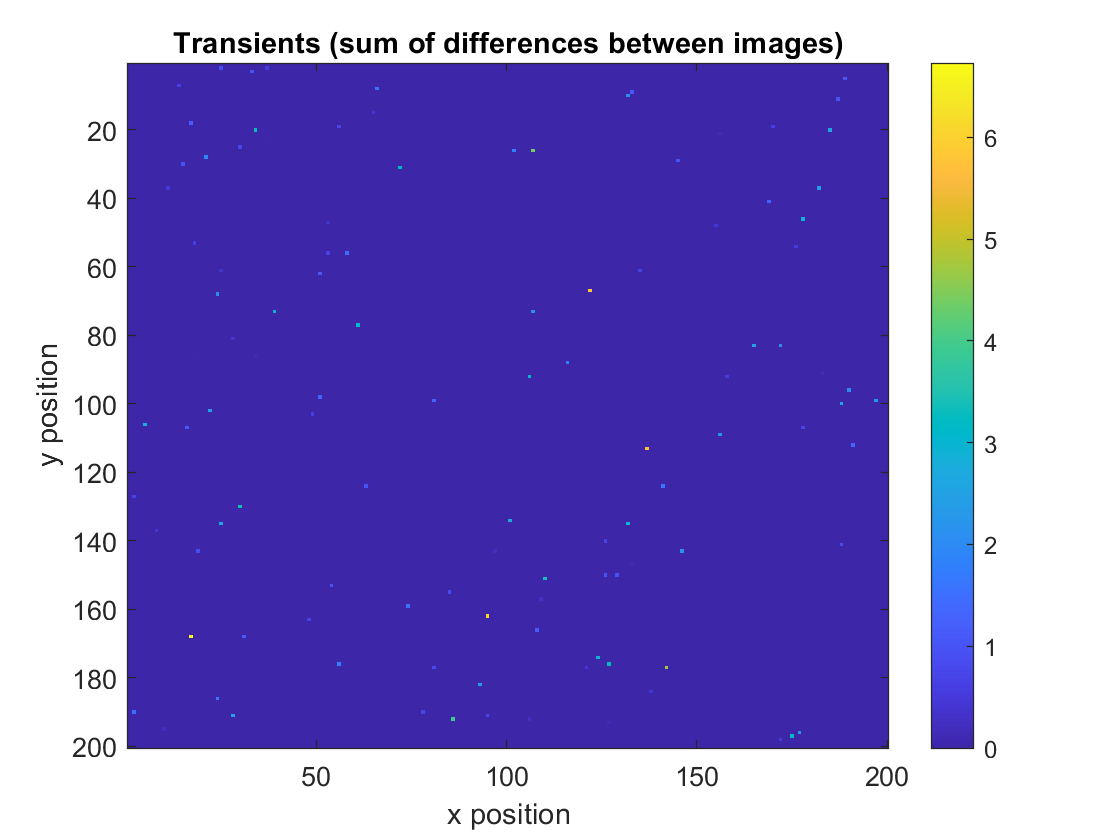

transients = objectfilter(squeeze(mydata(10, :, :)));

objects_set1 = zeros(5, 200, 200);
for ii = 2:2:10
    objects_set1(ii/2, :, :) = objectfilter(squeeze(mydata(ii, :, :))) - objectfilter(squeeze(mydata(ii-1, :, :)));
end

transients = abs(squeeze(sum(objects_set1, 1)));

clf;
imagesc(transients)
colorbar
title('Transients (sum of differences between images)')
xlabel('x position');
ylabel('y position');

Each of the points in this dataset represents a signal, or part of a signal, that is present in one image but in no others.  Many of these points are likely outliers from the background of one of the images. However, since the background is random and Gaussian, it is very unlikely that the same pixel will see an outlier more than once. The brightest object in this dataset is therefore the most likely candidate for a significant transient, such as a supernova. 

Another method one could take to find transients:

Step 1. Find the sum of all the image data sets

Step 2. Remove the background data

Step 3. Remove objects which are found in the same locations as objects that are present in all datasets

Through this process, one would inevitably sum a transient, a significant signal which is in a certain location only for one image. By removing the objects which stay in the same place throughout each image, the transient signal would stay in the final distribution.

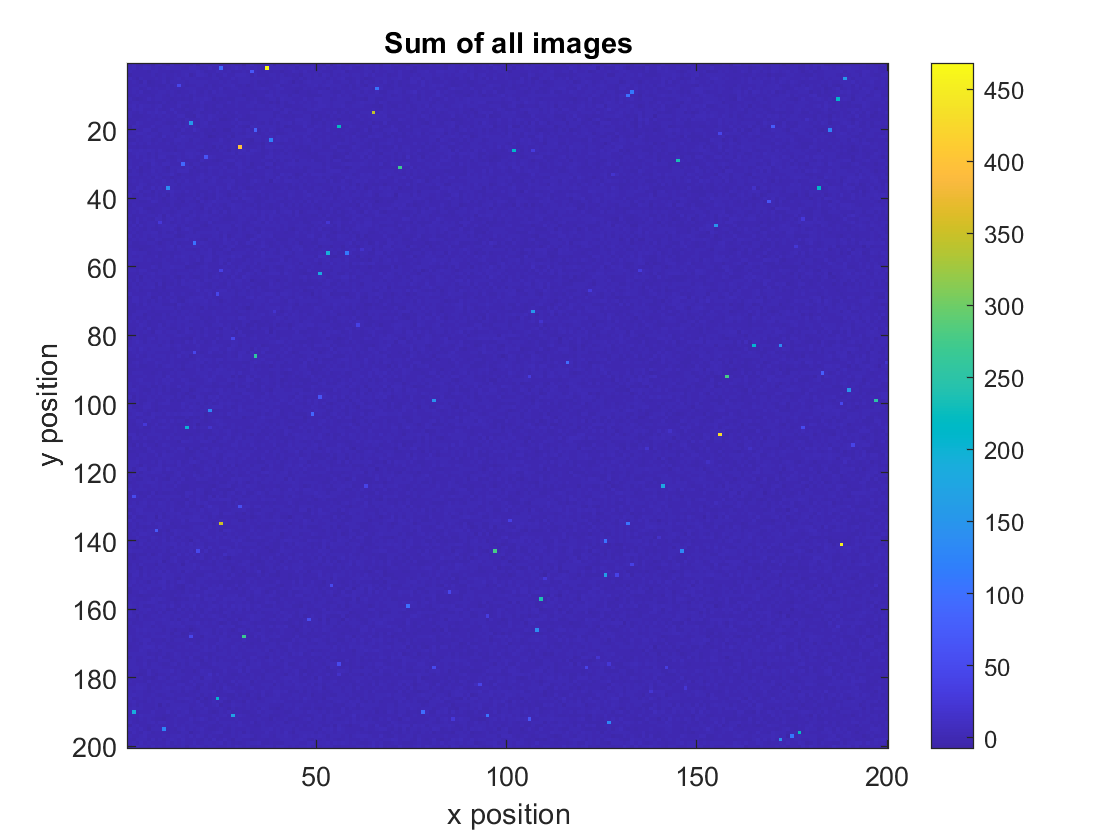

clf;

sum_dist = sum(mydata, 1);

imagesc(squeeze(sum_dist));
c = colorbar;
title('Sum of all images')
xlabel('x position');
ylabel('y position');

clf;

histogram(sum_dist, 'EdgeColor', 'none'), hold on;
set(gca, 'YScale', 'log')

%find profile of background
bkg = sum_dist(abs(sum_dist) < 10);

std_bkg = std(bkg);
xs = linspace(-10, 10, 1000);
ys = normpdf(xs, 0, std_bkg) .* 3e4;
%ys(1) = 1e-20;
%ys(end) = 1e-20;
plot(xs, ys, 'Linewidth', 2)
ylim([.8 1e4])
xlim([-10, 40])
title('Sum of all images')
%only choose 5 sigma events
all_objects = sum_dist .* (sum_dist > 5*std_bkg | sum_dist < -5*std_bkg);

clf;
imagesc(squeeze(all_objects));
c = colorbar;
title('All objects')

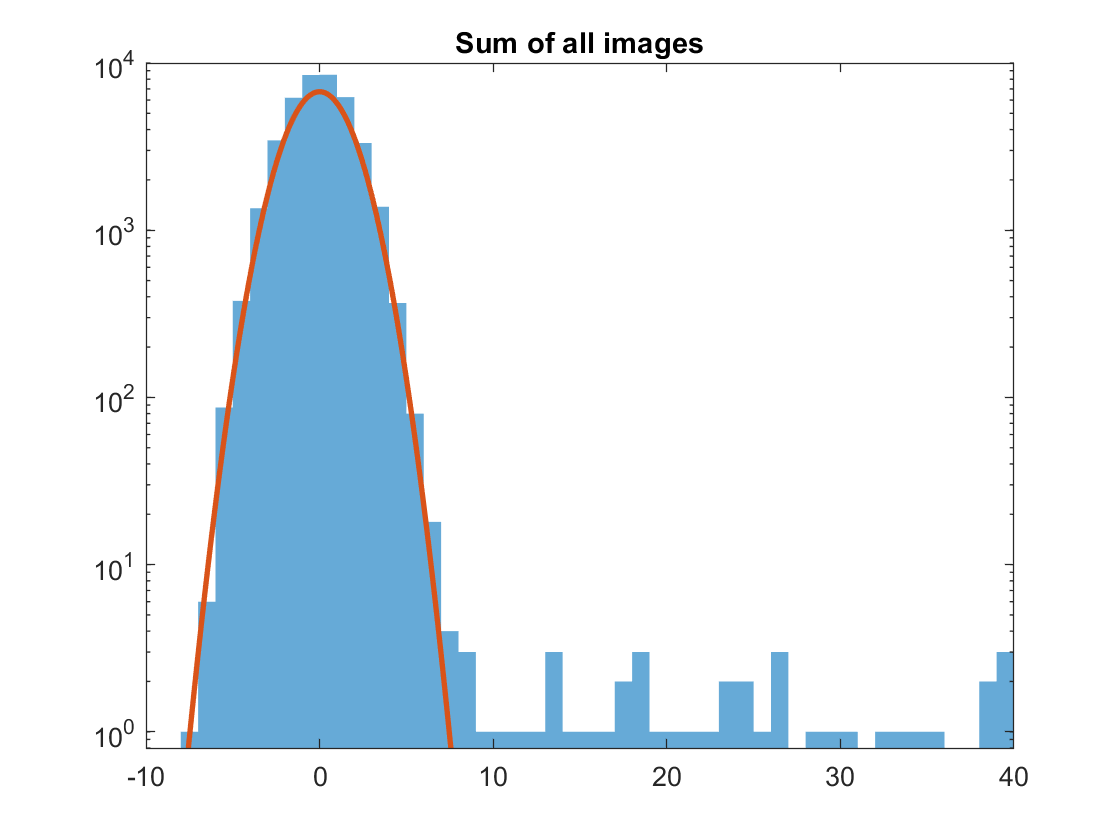

function objects = objectfilter(image)

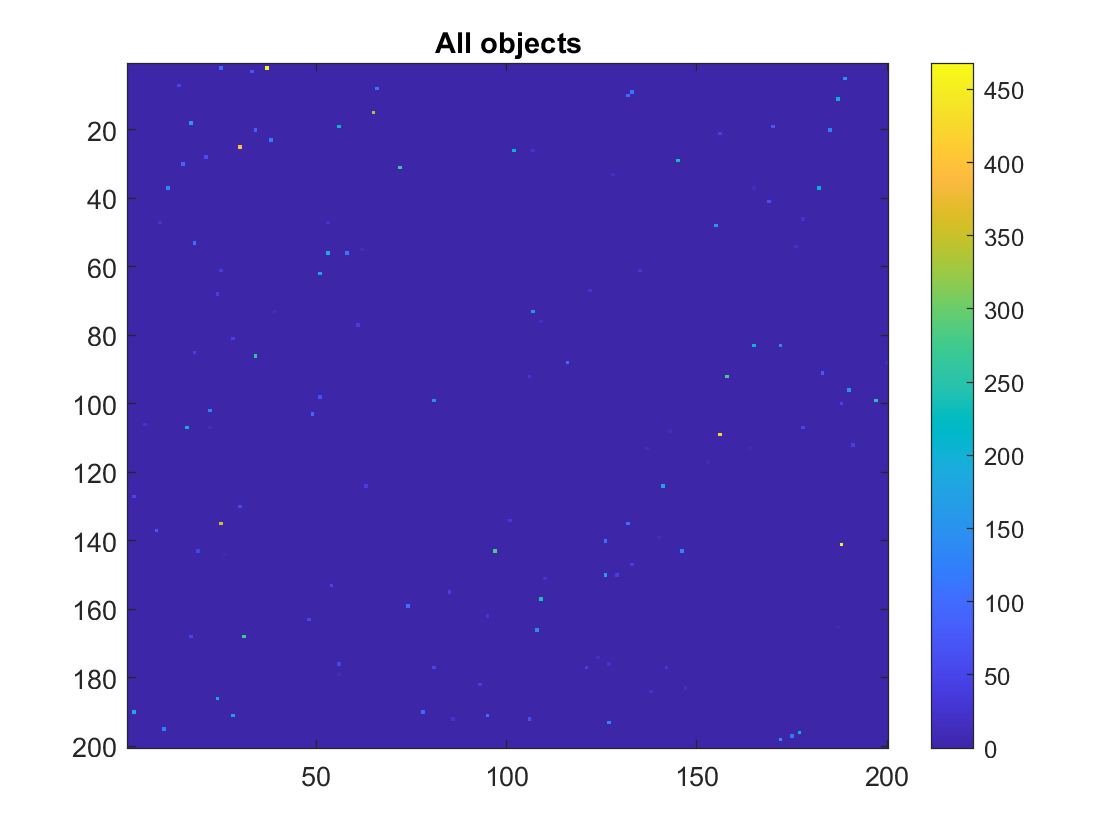

%Finds objects in the image data corresponding to significance of 5 sigma
bkg_limit = 2;
object_logical = (image < bkg_limit & image > -bkg_limit);
bkg = image(object_logical);
std_bkg = std(bkg);
objects = image .* (image > 5*std_bkg | image < -5*std_bkg);
end


function [f, P1] = fouriern(data)
    Fs = 10;            % Sampling frequency                    
    T = 1/Fs;           % Sampling period       
    L = 5400*80;        % Length of signal
    t = (0:L-1)*T;
    
    Y = fft(data);
    f = Fs*(0:(L/2))/L;
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
end